data = readtable("Five_times_Kinematics_HT_Query_Quadratic.xlsx")

data = 50×242 table
    reclutado    AgeGroup     BMI_Value       GroupName        x1_AAFEM    x2_AAFEM    x3_AAFEM    x4_AAFEM    x5_AAFEM    x1_AAIEM    x2_AAIEM    x3_AAIEM    x4_AAIEM    x5_AAIEM    x1_AKFEM    x2_AKFEM    x3_AKFEM    x4_AKFEM    x5_AKFEM    x1_AKAAM    x2_AKAAM    x3_AKAAM    x4_AKAAM    x5_AKAAM    x1_AKIEM    x2_AKIEM    x3_AKIEM    x4_AKIEM    x5_AKIEM    x1_AHPFEM    x2_AHPFEM    x3_AHPFEM    x4_AHPFEM    

isNum = varfun(@isnumeric, data, 'OutputFormat', 'uniform');
numericData = data(:, isNum);
X = table2array(numericData);
[n, p] = size(X);
fprintf('El dataset original tiene %d observaciones y %d variables.\n', n, p);

El dataset original tiene 50 observaciones y 239 variables.


Detección de **OUTLIERS y QQ-plots**:

Dimensión 1: 0 outliers encontrados.


col_clean =     34
    30
    11
    40
    85
   115
   119
   126
   127
   131


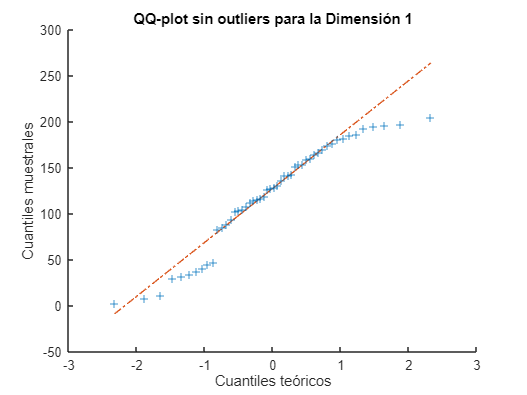

Dimensión 2: 2 outliers encontrados.


col_clean =     7.0000
    6.1000
    0.3000
    7.0000
   -7.1000
    1.4000
   -1.6000
   -4.9000
   -0.6000
   -1.6000


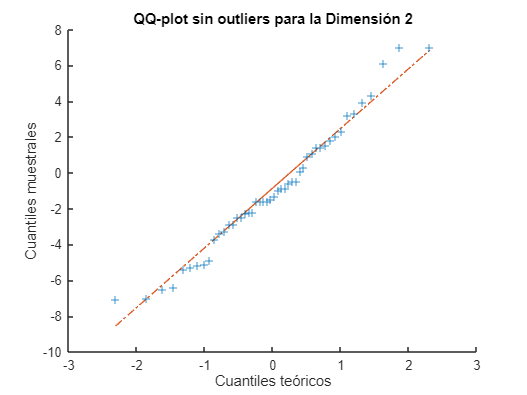

Dimensión 3: 0 outliers encontrados.


col_clean =     4.9000
    3.9000
         0
    3.8000
   -1.5000
   -1.3000
   -4.1000
    1.3000
    3.1000
   -0.2000


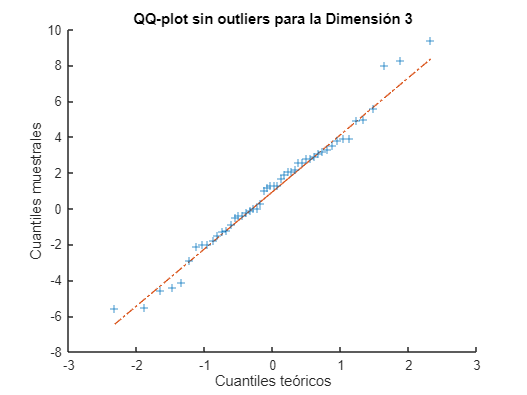

Dimensión 4: 5 outliers encontrados.


col_clean =    12.0000
    5.7000
   10.4000
    2.9000
    3.7000
    5.1000
    4.4000
    7.8000
    6.0000
    8.5000


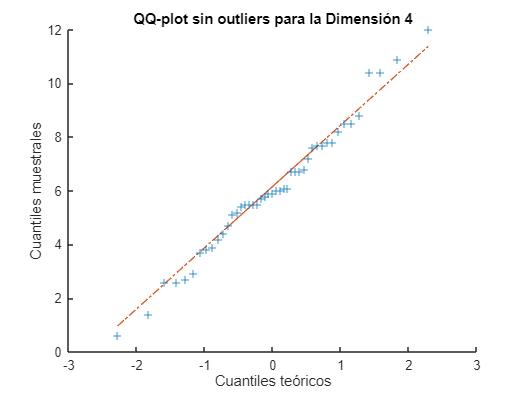

Dimensión 5: 2 outliers encontrados.


col_clean =    18.2000
   13.6000
   13.6000
    7.6000
    9.2000
   13.0000
    7.9000
   13.7000
   14.9000
   17.3000


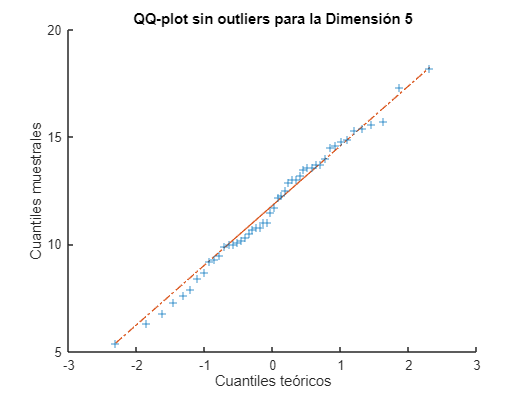

Dimensión 6: 0 outliers encontrados.


col_clean =     6.5000
   -6.2000
   -4.5000
  -11.3000
  -11.9000
   -6.3000
  -13.0000
   -9.3000
   -4.5000
   -3.5000


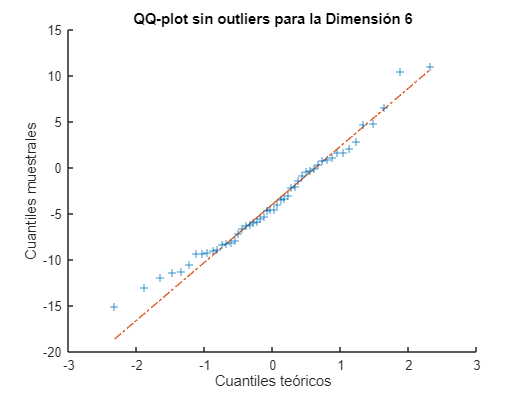

Dimensión 7: 1 outliers encontrados.


col_clean =   -11.1000
  -18.3000
  -10.3000
   -9.6000
  -12.6000
   -5.9000
   -5.3000
   -9.5000
   -1.9000
   -7.5000


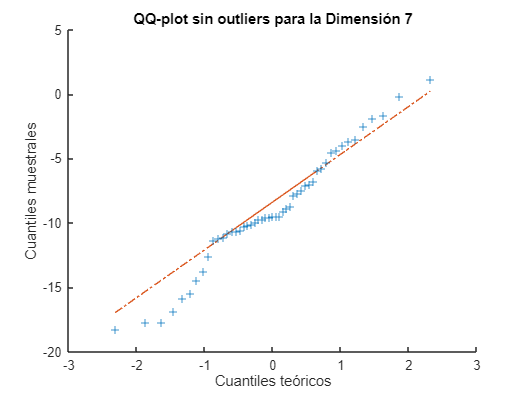

Dimensión 8: 0 outliers encontrados.


col_clean =    -7.9000
  -14.4000
   -7.1000
   -2.6000
  -11.3000
    2.0000
   -0.6000
   -6.7000
   -2.3000
   -2.3000


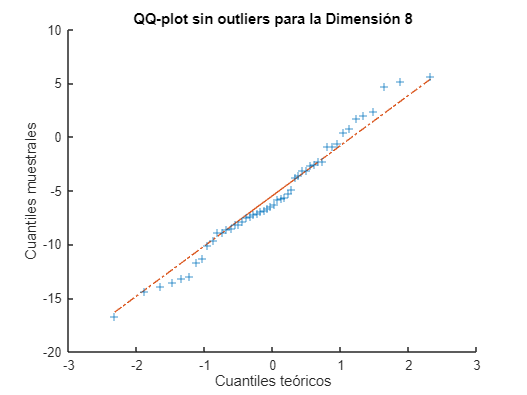

Dimensión 9: 0 outliers encontrados.


col_clean =    -9.5000
  -16.4000
   -7.5000
   -4.5000
  -12.8000
    1.9000
   -1.7000
   -6.2000
   -2.3000
   -4.0000


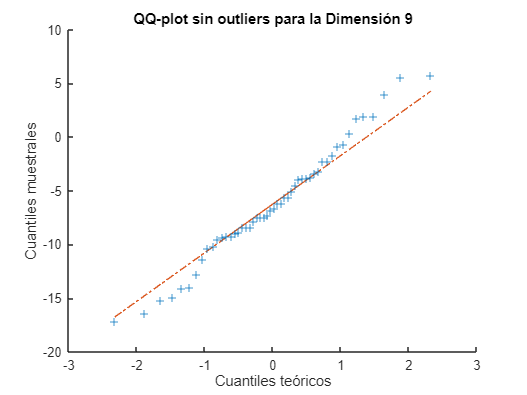

Dimensión 10: 0 outliers encontrados.


col_clean =   -10.8000
  -17.9000
  -10.8000
   -4.6000
  -15.2000
    1.0000
   -4.6000
   -5.6000
   -3.0000
   -5.1000


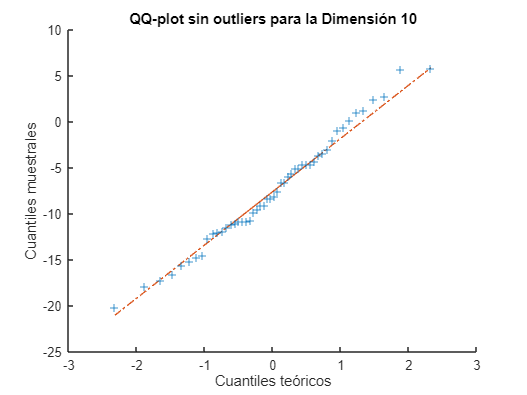

Dimensión 11: 0 outliers encontrados.


col_clean =    -6.0000
  -13.4000
   -4.4000
    3.5000
   -7.8000
   10.0000
    2.3000
   -0.1000
    1.4000
    0.3000


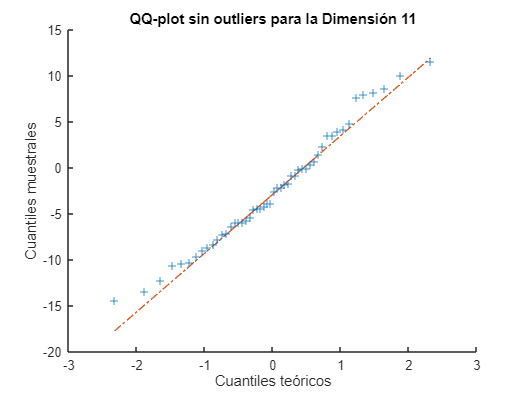

Dimensión 12: 2 outliers encontrados.


col_clean =     6.4000
         0
    3.1000
    4.1000
    3.3000
    5.3000
    4.2000
    9.7000
   -0.4000
    6.3000


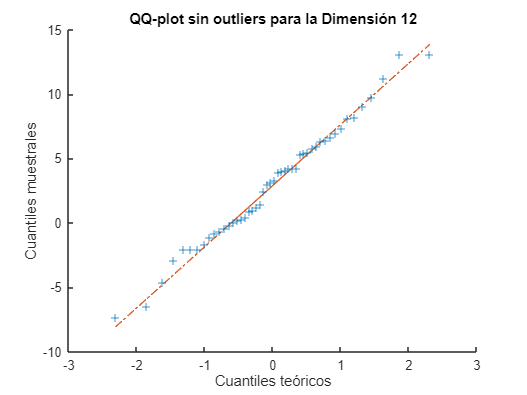

Dimensión 13: 1 outliers encontrados.


col_clean =    13.5000
    5.2000
   11.8000
   13.9000
    0.2000
   11.1000
   13.3000
   19.9000
   12.0000
   16.1000


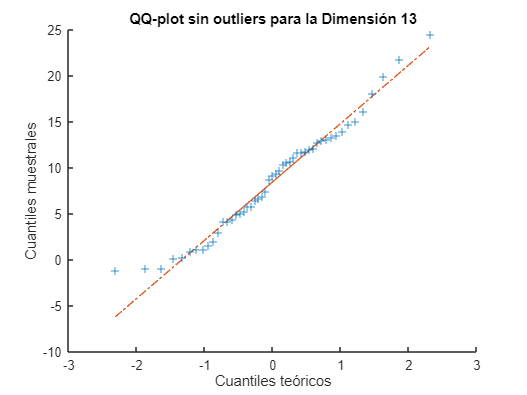

Dimensión 14: 0 outliers encontrados.


col_clean =    11.4000
    2.2000
    2.1000
    2.1000
   -4.7000
    3.8000
    8.2000
   19.5000
   10.7000
    8.6000


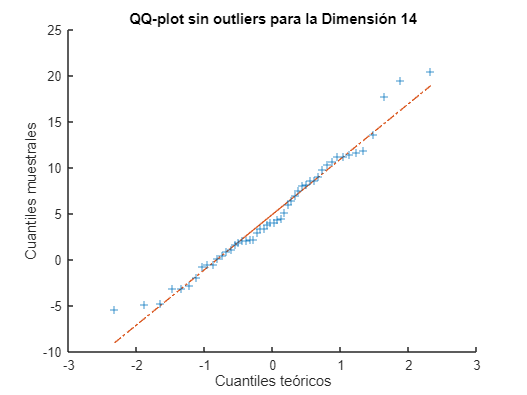

Dimensión 15: 0 outliers encontrados.


col_clean =    13.2000
    3.1000
   -0.4000
   -7.3000
   -4.8000
   -1.1000
    5.5000
   19.1000
    9.6000
    6.2000


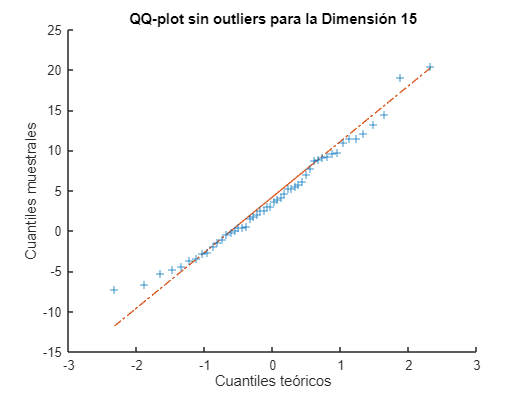

Dimensión 16: 0 outliers encontrados.


col_clean =    37.4000
   31.2000
   30.6000
   20.6000
   24.0000
   38.6000
   33.9000
   37.7000
   34.2000
   36.3000


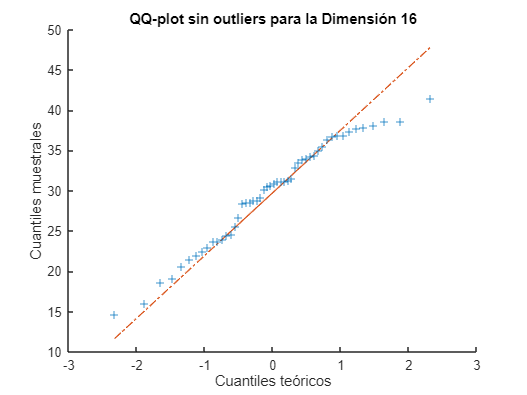

Dimensión 17: 0 outliers encontrados.


col_clean =    -2.9000
    0.7000
   -4.6000
   -8.4000
    2.2000
   -3.7000
    1.8000
   -9.9000
    1.7000
   -0.6000


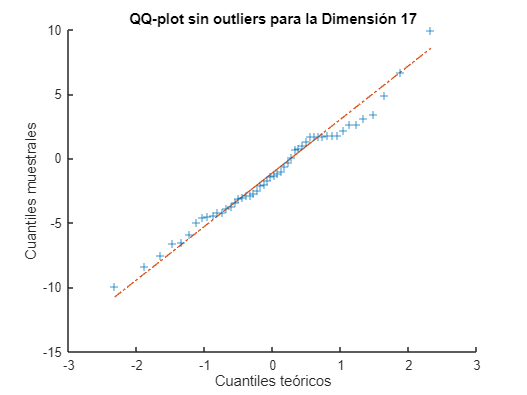

Dimensión 18: 1 outliers encontrados.


col_clean =    -2.1000
    2.1000
   -2.3000
   -4.2000
    5.6000
   -2.1000
    3.6000
   -8.0000
    4.7000
   -0.7000


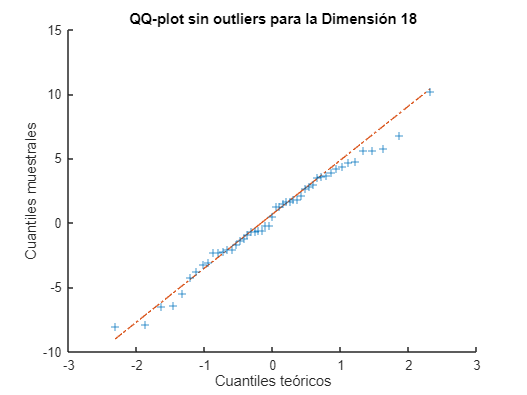

Dimensión 19: 1 outliers encontrados.


col_clean =    -2.2000
    2.8000
   -3.4000
   -5.8000
    4.5000
   -1.0000
    1.9000
   -7.5000
    4.6000
   -2.5000


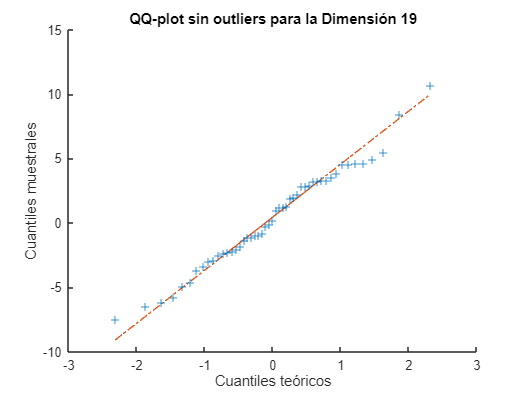

Dimensión 20: 1 outliers encontrados.


col_clean =    -3.9000
    1.0000
   -3.3000
   -2.7000
    4.2000
   -1.7000
         0
   -7.9000
    4.6000
   -1.7000


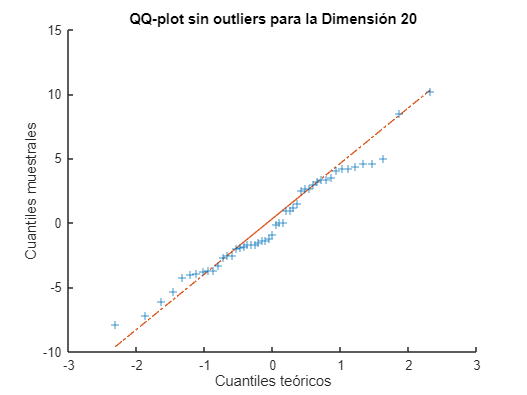

Dimensión 21: 1 outliers encontrados.


col_clean =    -7.7000
    9.5000
   -0.7000
   -4.5000
    5.0000
    0.5000
    2.4000
    3.1000
   -7.9000
    6.9000


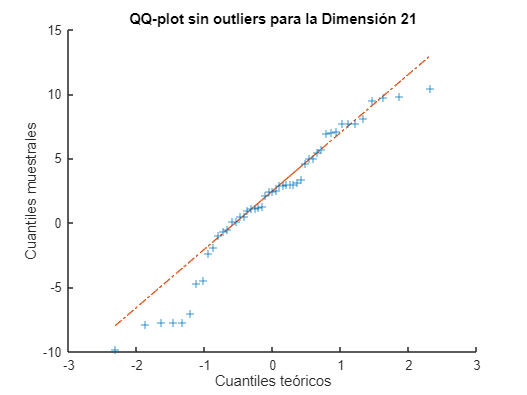

Dimensión 22: 1 outliers encontrados.


col_clean =     5.8000
  -16.7000
   -9.5000
  -21.8000
   -3.4000
    0.1000
  -14.4000
    0.6000
   -2.7000
   -9.4000


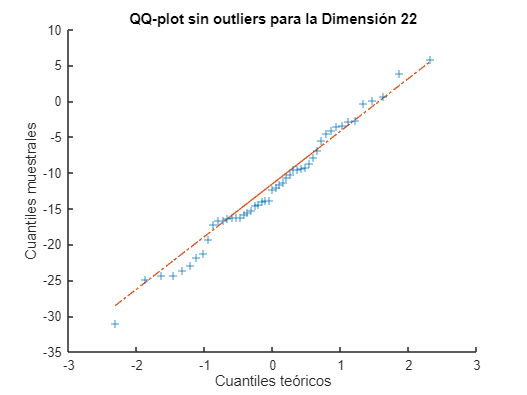

Dimensión 23: 2 outliers encontrados.


col_clean =     7.2000
  -16.0000
   -6.2000
  -21.9000
    1.3000
    7.2000
  -14.6000
    2.5000
    0.9000
   -3.9000


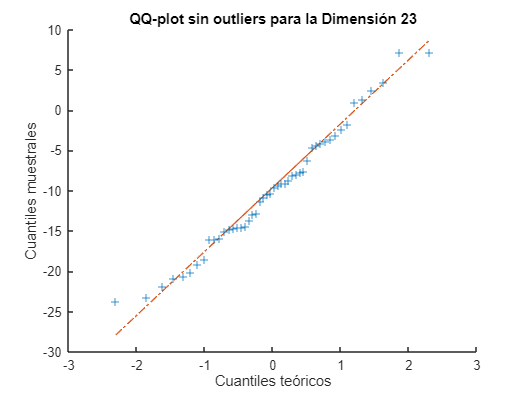

Dimensión 24: 0 outliers encontrados.


col_clean =     5.8000
  -16.5000
  -11.4000
   12.1000
  -23.8000
   -1.3000
    3.9000
  -14.2000
    0.9000
   -1.4000


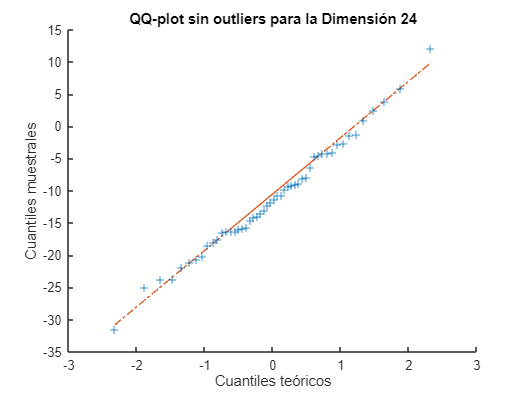

Dimensión 25: 0 outliers encontrados.


col_clean =     6.1000
  -15.8000
  -11.8000
    8.8000
  -23.9000
   -1.9000
    4.9000
  -15.1000
   -1.1000
   -3.0000


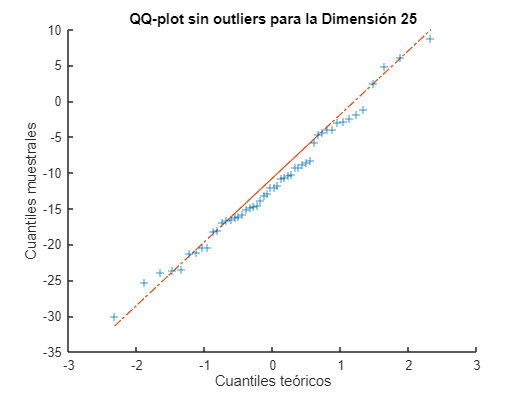

Dimensión 26: 0 outliers encontrados.


col_clean =     9.8000
  -12.3000
   -4.8000
   17.3000
  -18.3000
    9.0000
   14.5000
  -10.2000
    9.3000
    6.7000


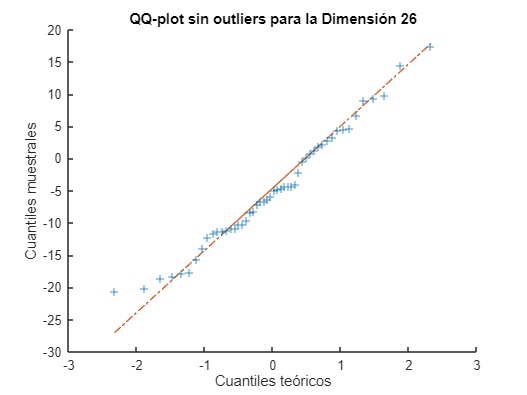

Dimensión 27: 1 outliers encontrados.


col_clean =    40.6000
   30.9000
   24.9000
   32.7000
   15.0000
   24.8000
   37.1000
   50.0000
   24.2000
   27.2000


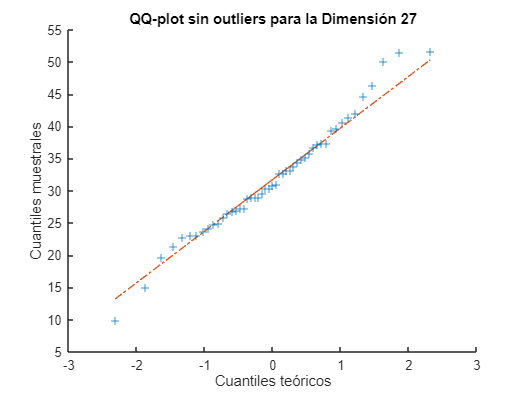

Dimensión 28: 2 outliers encontrados.


col_clean =    33.4000
   16.4000
   17.2000
   22.6000
   -2.0000
    9.8000
   24.5000
   33.5000
    9.1000
   24.1000


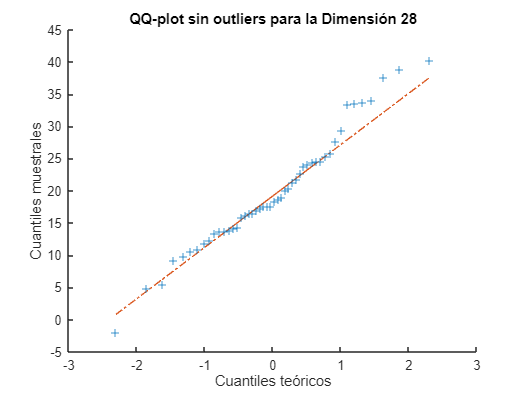

Dimensión 29: 1 outliers encontrados.


col_clean =    20.8000
    6.7000
    1.0000
    3.3000
  -11.9000
   -4.6000
   11.2000
   29.5000
    2.1000
    8.1000


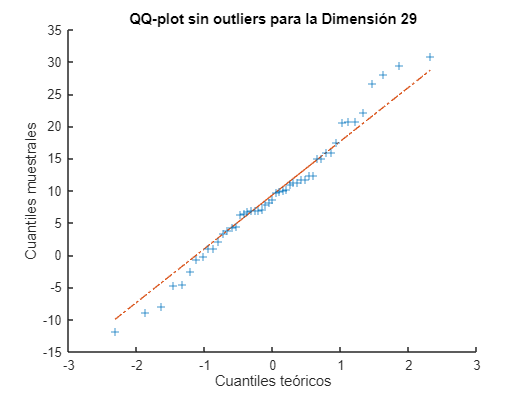

Dimensión 30: 1 outliers encontrados.


col_clean =     9.6000
   -3.8000
  -17.7000
  -18.6000
  -20.3000
  -18.5000
   -3.3000
   23.5000
   -8.2000
  -10.8000


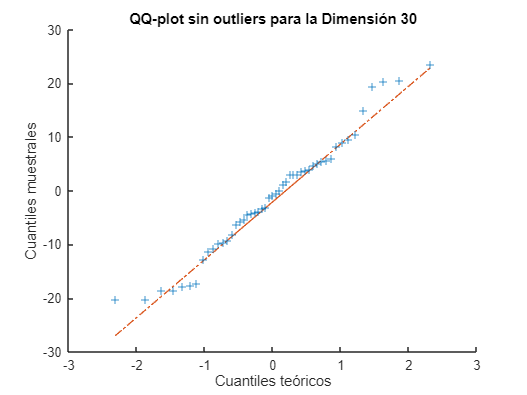

Dimensión 31: 1 outliers encontrados.


col_clean =    10.4000
   -0.5000
  -13.5000
  -17.6000
  -18.6000
  -12.1000
   -1.0000
   20.6000
   -8.7000
   -5.8000


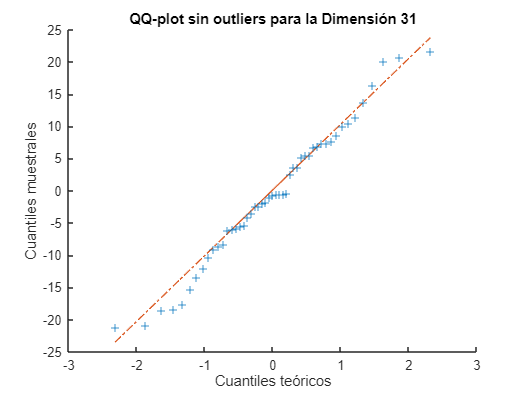

Dimensión 32: 0 outliers encontrados.


col_clean =    -1.0000
    1.6000
    4.2000
   10.2000
    0.8000
    6.9000
   -6.3000
    0.3000
   -6.8000
    2.4000


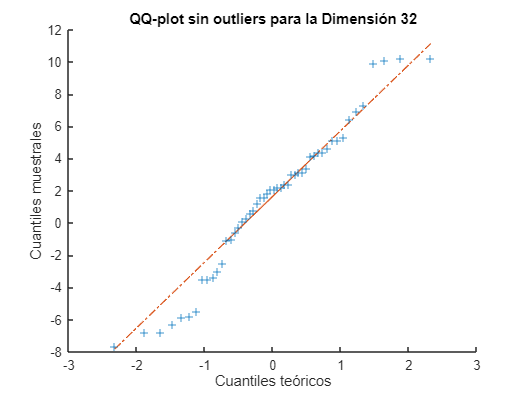

Dimensión 33: 1 outliers encontrados.


col_clean =     6.9000
    7.7000
    9.9000
   13.3000
    5.6000
   11.7000
    2.0000
    5.7000
   -3.3000
   10.4000


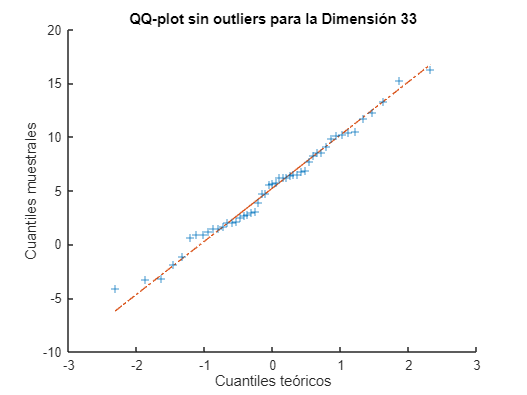

Dimensión 34: 1 outliers encontrados.


col_clean =     6.6000
    4.1000
    8.7000
   10.2000
    5.7000
    5.0000
   -0.5000
    3.9000
   -2.6000
    8.1000


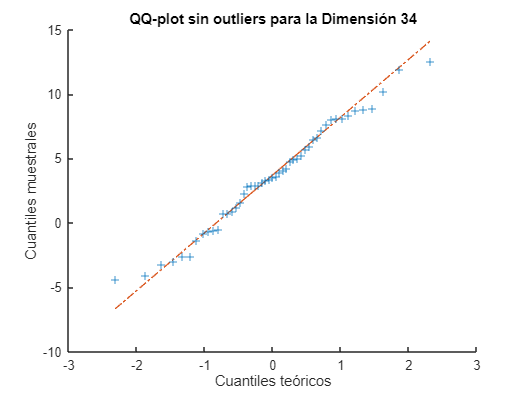

Dimensión 35: 1 outliers encontrados.


col_clean =     6.9000
    4.2000
   10.2000
    6.9000
    5.7000
    3.9000
   -3.6000
    2.5000
   -1.3000
    4.4000


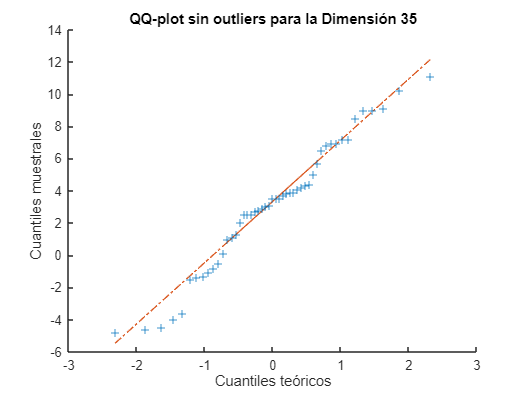

Dimensión 36: 3 outliers encontrados.


col_clean =    -1.1000
   -5.4000
    3.9000
   -3.7000
   -1.2000
   -5.1000
   -9.6000
   -7.4000
   -0.8000
   -3.3000


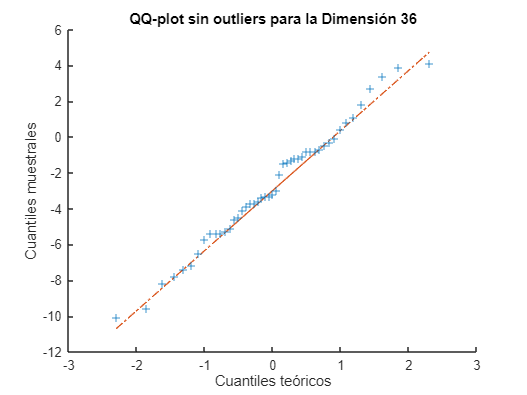

Dimensión 37: 0 outliers encontrados.


col_clean =   -11.4000
   12.2000
    1.5000
   -2.9000
  -18.7000
    7.0000
    9.6000
  -17.5000
  -14.8000
   -2.5000


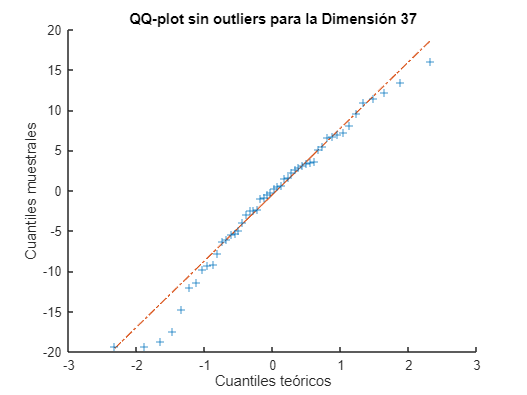

Dimensión 38: 0 outliers encontrados.


col_clean =   -12.4000
   12.8000
    5.7000
    6.2000
  -13.1000
    7.6000
    9.9000
  -13.6000
  -11.8000
    6.8000


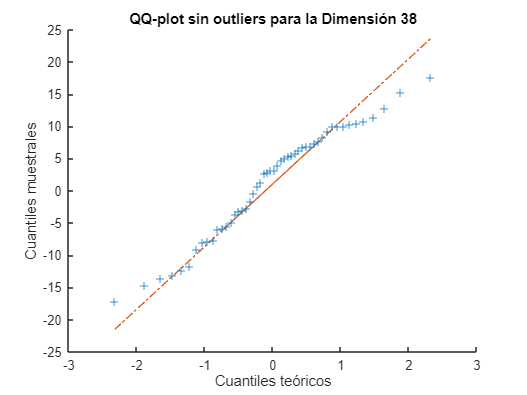

Dimensión 39: 0 outliers encontrados.


col_clean =   -16.9000
    9.7000
   -2.7000
  -10.9000
  -11.6000
    3.4000
    7.2000
  -15.7000
   -9.8000
   -4.7000


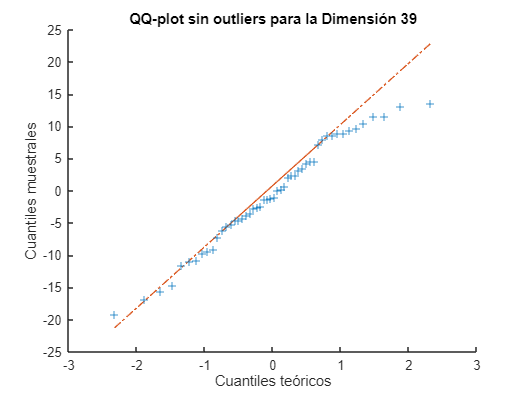

Dimensión 40: 0 outliers encontrados.


col_clean =   -21.7000
    9.0000
   -2.3000
  -19.5000
  -11.8000
   -0.7000
    3.1000
  -17.5000
   -7.4000
   -9.1000


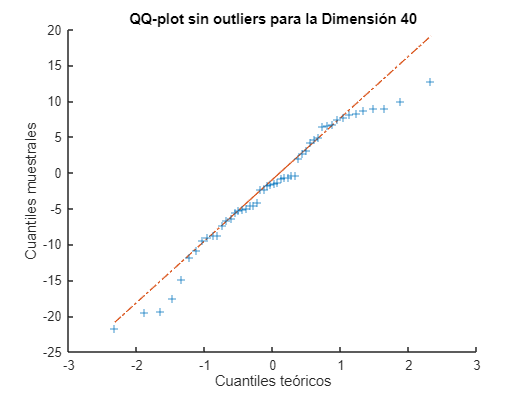

Dimensión 41: 0 outliers encontrados.


col_clean =   -18.4000
   10.2000
   -1.6000
  -17.9000
   -9.5000
    2.9000
    6.9000
  -20.9000
   -5.9000
   -5.7000


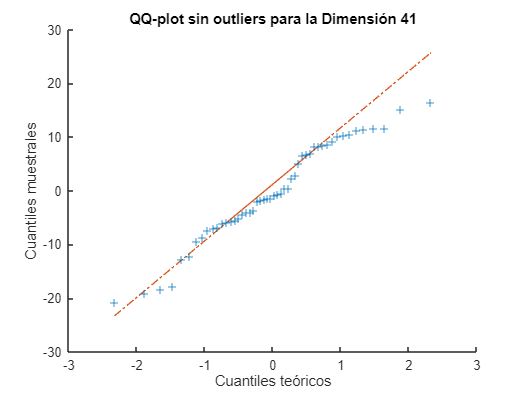

Dimensión 42: 0 outliers encontrados.


col_clean =    18.6000
   10.1000
    3.4000
   10.5000
   -4.1000
    0.3000
   13.3000
   20.0000
    2.8000
    5.3000


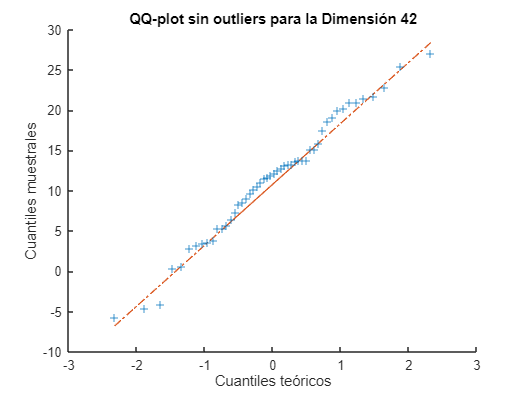

Dimensión 43: 0 outliers encontrados.


col_clean =    19.0000
    7.7000
    2.0000
    7.8000
   -2.2000
    0.2000
   10.9000
   19.5000
    3.2000
    5.8000


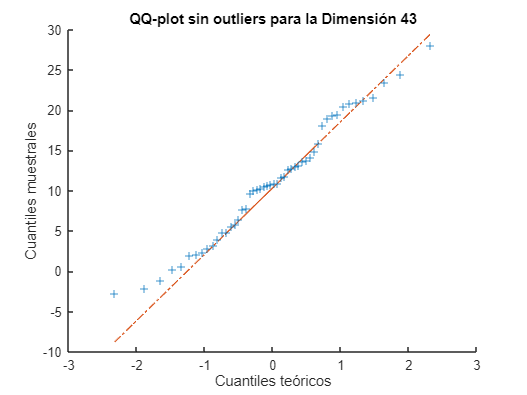

Dimensión 44: 0 outliers encontrados.


col_clean =    18.0000
    9.9000
    2.4000
    9.9000
   -2.0000
   -0.2000
   12.1000
   19.9000
    2.7000
    5.2000


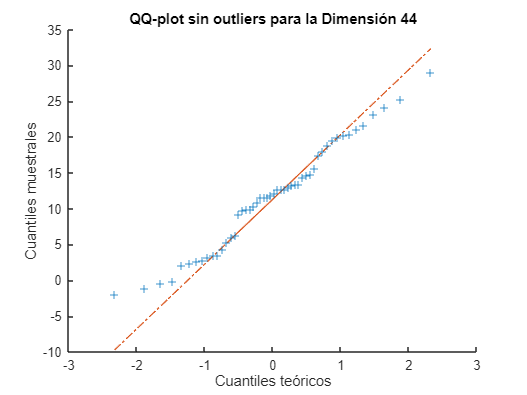

Dimensión 45: 0 outliers encontrados.


col_clean =    17.1000
   10.8000
    0.4000
    9.5000
   -1.8000
    1.0000
   14.4000
   21.1000
    3.3000
    3.3000


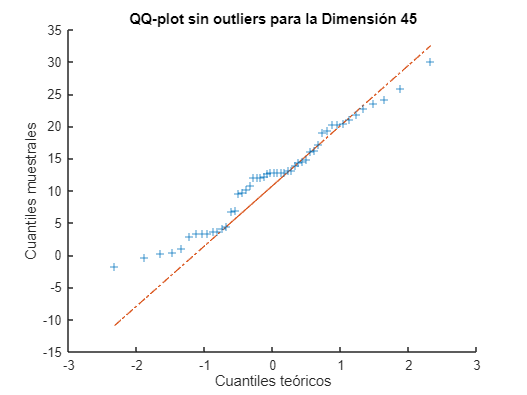

Dimensión 46: 0 outliers encontrados.


col_clean =    16.2000
    9.3000
    0.5000
    7.5000
   -3.0000
   -0.9000
   13.4000
   19.8000
    1.9000
    4.4000


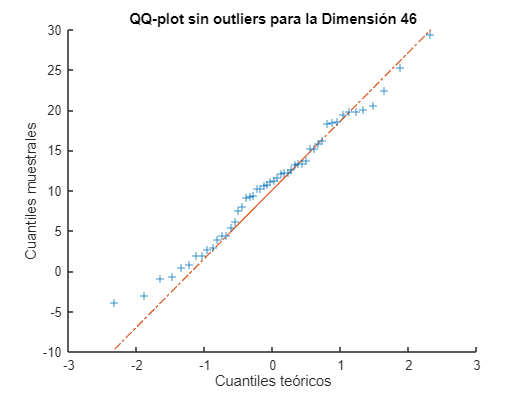

Dimensión 47: 1 outliers encontrados.


col_clean =    -0.3000
    0.2000
   -0.2000
    0.9000
    0.5000
    1.5000
   -2.6000
   -2.4000
   -1.0000
    1.6000


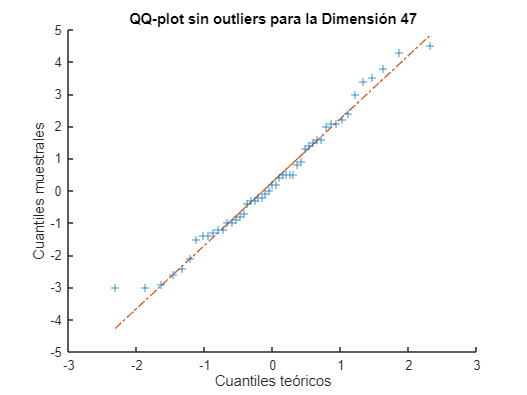

Dimensión 48: 1 outliers encontrados.


col_clean =     3.3000
    2.4000
    3.8000
    3.3000
    2.7000
    4.9000
    1.9000
   -2.2000
   -0.2000
    4.9000


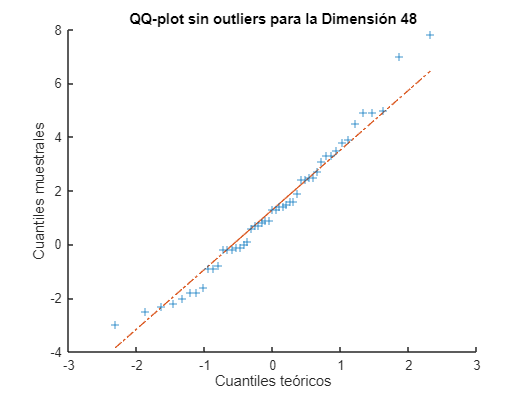

Dimensión 49: 2 outliers encontrados.


col_clean =     0.2000
   -0.3000
    1.7000
    0.1000
    0.7000
   -0.2000
   -2.4000
   -3.9000
   -1.6000
    1.9000


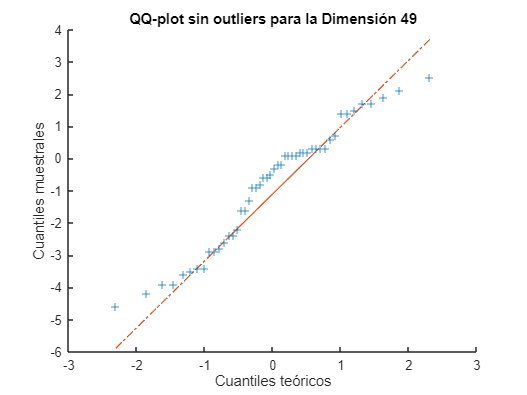

Dimensión 50: 0 outliers encontrados.


col_clean = 50×1
   -0.2000
   -0.5000
    1.5000
   -0.9000
    0.5000
   -0.9000
   -4.2000
   -3.7000
   -1.7000
    0.7000


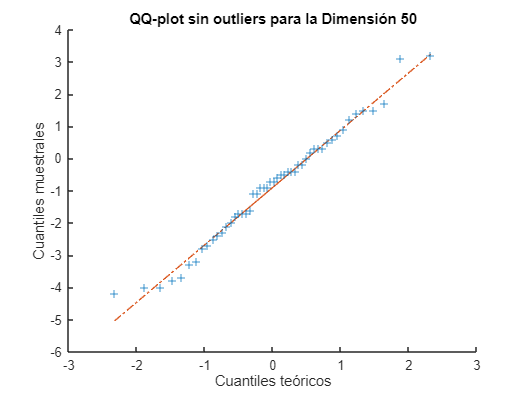

Dimensión 51: 1 outliers encontrados.


col_clean = 49×1
   -4.4000
   -4.0000
   -0.7000
   -3.1000
   -1.0000
   -4.1000
   -3.9000
   -3.4000
   -2.0000
   -3.1000


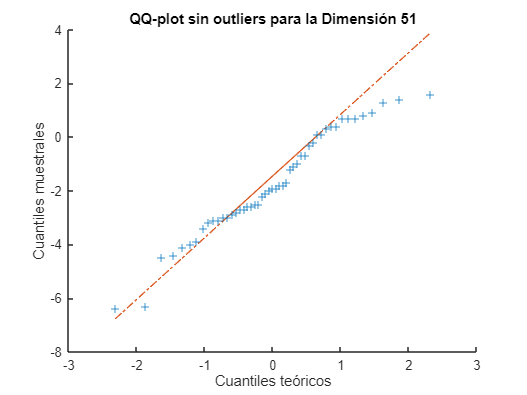

Dimensión 52: 1 outliers encontrados.


col_clean = 49×1
    2.5000
    2.1000
    1.4000
    5.9000
   -4.1000
    8.6000
   -2.7000
    4.9000
    4.8000
    1.7000


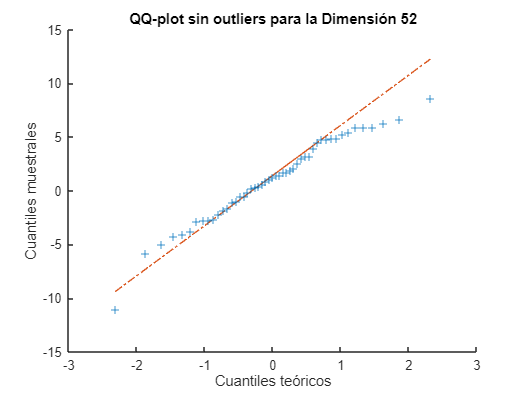

Dimensión 53: 1 outliers encontrados.


col_clean = 49×1
    2.9000
    2.1000
    1.6000
    6.4000
   -0.2000
   10.1000
   -0.2000
    7.9000
    4.4000
    2.6000


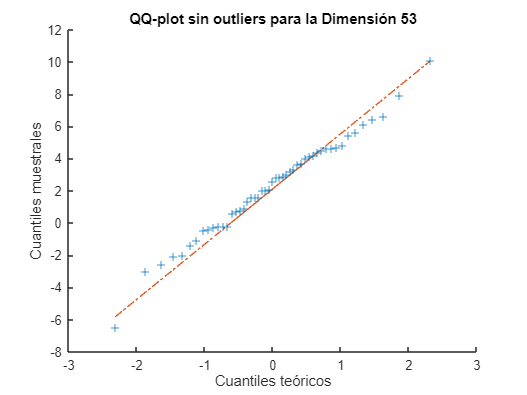

Dimensión 54: 1 outliers encontrados.


col_clean = 49×1
    1.1000
    3.1000
   -0.9000
    4.6000
    2.5000
    5.4000
   -0.4000
    8.2000
    1.5000
    3.2000


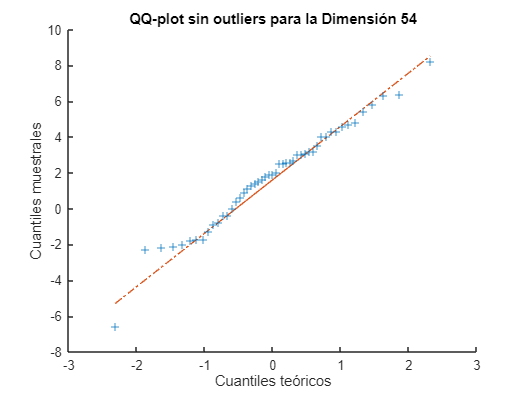

Dimensión 55: 0 outliers encontrados.


col_clean = 50×1
    8.1000
   -2.4000
    3.0000
   -3.7000
    2.2000
   -0.2000
   -4.3000
   -3.1000
    7.4000
   -4.7000


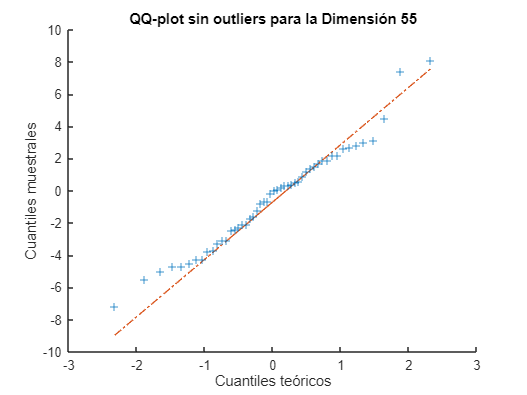

Dimensión 56: 0 outliers encontrados.


col_clean = 50×1
    5.4000
   -2.5000
    3.4000
   -3.5000
    2.7000
   -3.1000
   -7.4000
   -5.7000
    4.4000
   -6.7000


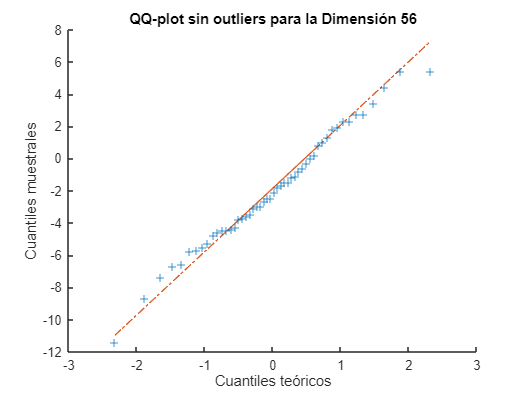

Dimensión 57: 0 outliers encontrados.


col_clean = 50×1
   -9.4000
   -4.0000
    2.5000
   -0.1000
    4.7000
    1.1000
    0.6000
    1.6000
   -0.3000
   -6.6000


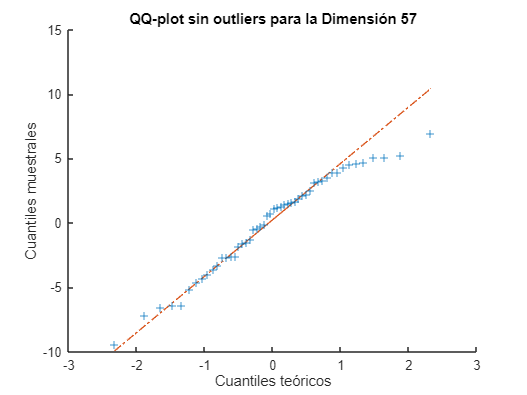

Dimensión 58: 0 outliers encontrados.


col_clean = 50×1
  -13.6000
   -5.6000
   -2.2000
   -4.0000
    0.3000
   -4.2000
   -5.6000
    2.3000
   -3.3000
  -10.5000


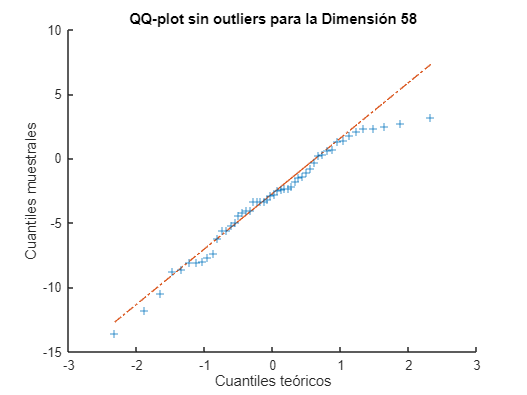

Dimensión 59: 0 outliers encontrados.


col_clean = 50×1
   -5.6000
   -1.4000
   -0.2000
    2.1000
    2.5000
    1.0000
    0.3000
    5.5000
   -1.2000
   -5.6000


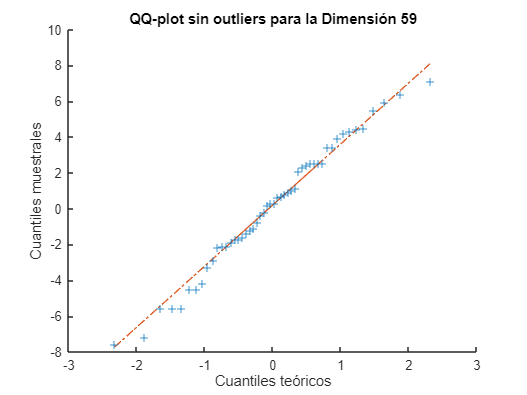

Dimensión 60: 0 outliers encontrados.


col_clean = 50×1
   -2.2000
   -0.1000
    0.7000
    3.9000
    3.2000
    2.5000
    5.6000
    7.8000
    0.3000
   -3.2000


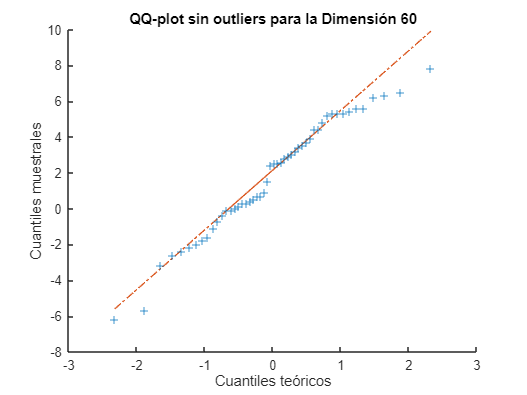

Dimensión 61: 0 outliers encontrados.


col_clean = 50×1
    4.9000
    2.3000
    3.7000
    7.3000
    5.9000
    7.6000
   13.8000
    8.6000
    4.2000
    0.1000


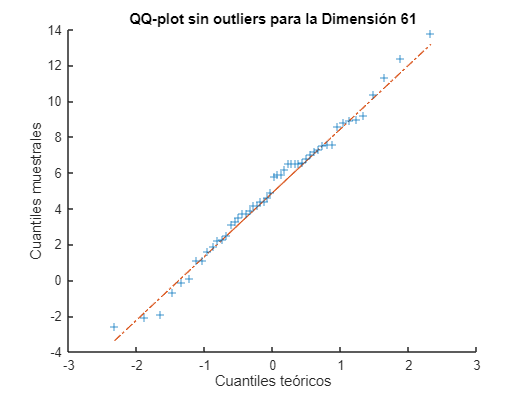

Dimensión 62: 1 outliers encontrados.


col_clean = 49×1
    3.8000
    2.7000
    4.6000
    5.9000
   -3.7000
   18.2000
   -5.9000
   10.3000
    7.4000
    1.0000


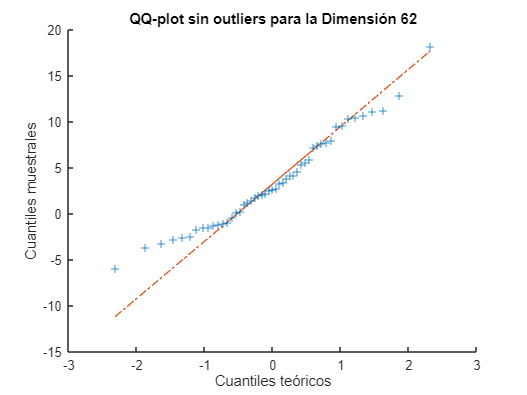

Dimensión 63: 1 outliers encontrados.


col_clean = 49×1
    1.9000
    2.9000
    4.4000
    5.5000
   -3.6000
   16.2000
   -7.8000
   11.1000
    6.3000
    0.1000


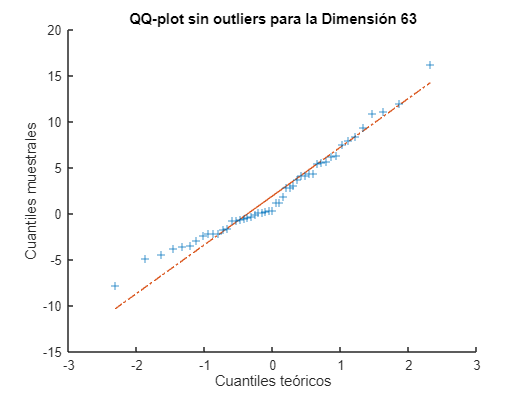

Dimensión 64: 1 outliers encontrados.


col_clean = 49×1
   -2.6000
    1.1000
   -1.0000
    1.8000
   -6.4000
    9.9000
  -11.0000
    7.4000
    0.9000
   -2.0000


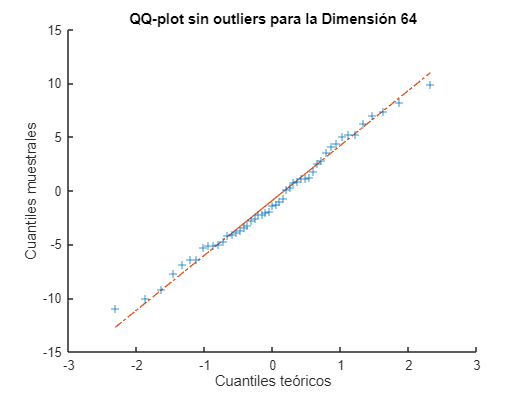

Dimensión 65: 2 outliers encontrados.


col_clean = 48×1
   -5.7000
   -1.3000
   -5.6000
         0
   -9.8000
    1.1000
    4.6000
   -5.2000
   -5.9000
   -9.9000


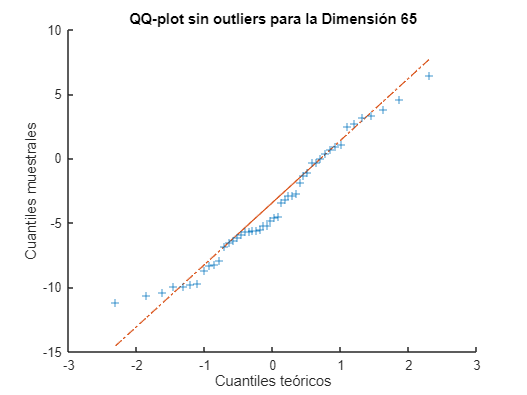

Dimensión 66: 1 outliers encontrados.


col_clean = 49×1
   -3.8000
   -1.1000
   -5.0000
    0.8000
   -9.7000
    1.4000
  -17.3000
    1.2000
   -6.8000
   -5.7000


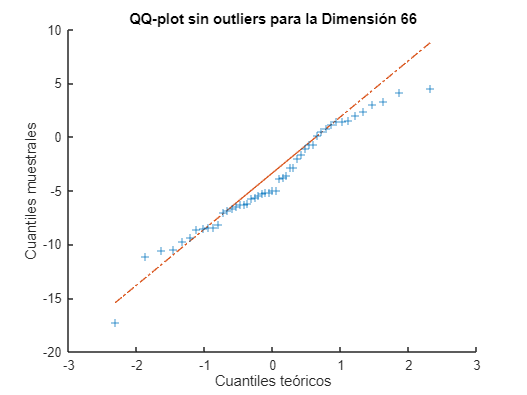

Dimensión 67: 1 outliers encontrados.


col_clean = 49×1
    0.5000
    2.9000
    5.6000
   12.2000
    3.7000
   10.8000
    5.4000
    6.0000
    6.5000
    4.6000


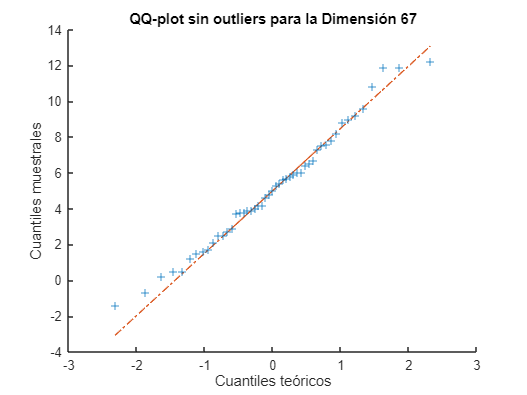

Dimensión 68: 1 outliers encontrados.


col_clean = 49×1
    1.5000
    2.1000
    6.0000
   12.5000
    2.1000
    8.3000
    4.3000
    5.1000
    4.1000
    3.5000


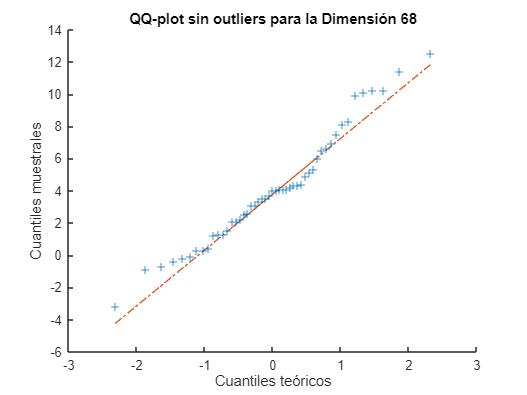

Dimensión 69: 1 outliers encontrados.


col_clean = 49×1
    1.3000
    4.3000
    6.0000
   12.8000
    2.7000
    9.3000
    4.7000
    7.1000
    4.9000
    4.1000


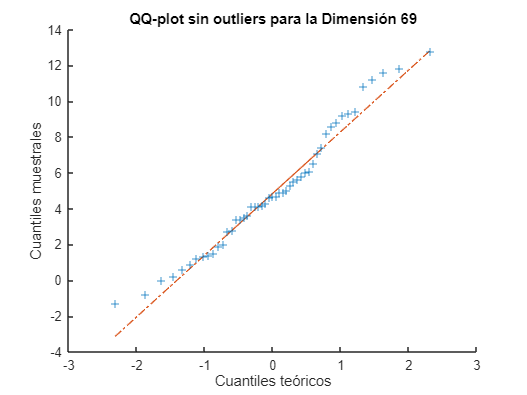

Dimensión 70: 1 outliers encontrados.


col_clean = 49×1
    0.8000
    5.0000
    5.9000
   12.8000
    3.9000
    9.0000
    4.7000
    8.7000
    4.9000
    5.5000


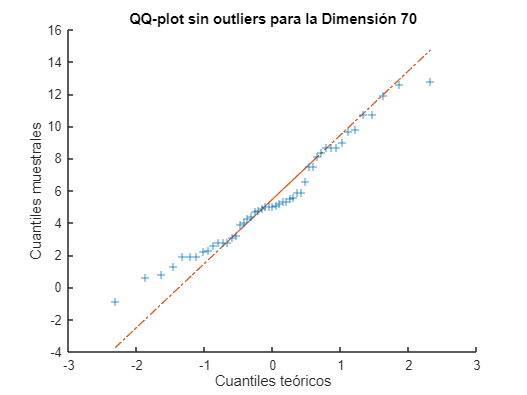

Dimensión 71: 1 outliers encontrados.


col_clean = 49×1
   -1.6000
    4.2000
    4.9000
   11.9000
    1.2000
    6.0000
    3.4000
    6.8000
    2.1000
    5.3000


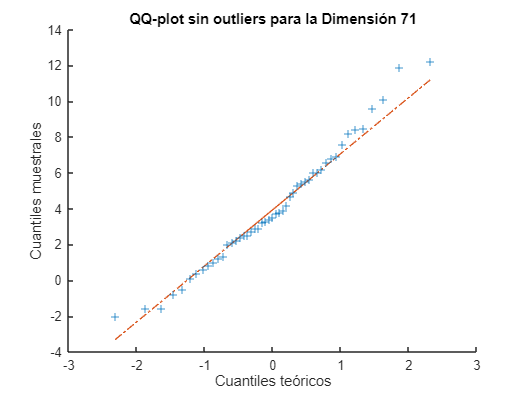

Dimensión 72: 1 outliers encontrados.


col_clean = 49×1
   -3.9000
   -2.1000
    0.7000
    0.7000
   -0.5000
    0.5000
   -0.3000
   -3.1000
   -0.8000
   -3.1000


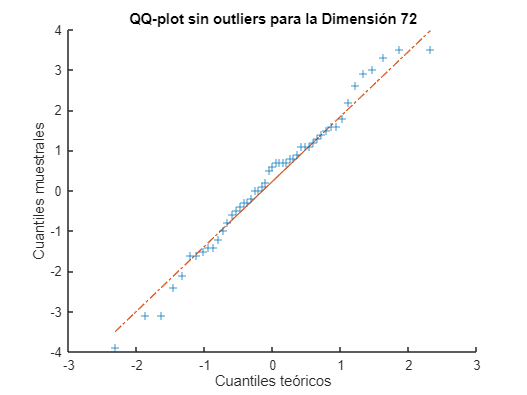

Dimensión 73: 1 outliers encontrados.


col_clean = 49×1
   -5.9000
   -1.9000
   -0.1000
   -1.1000
   -2.6000
   -1.5000
   -3.3000
   -2.9000
   -3.0000
   -3.7000


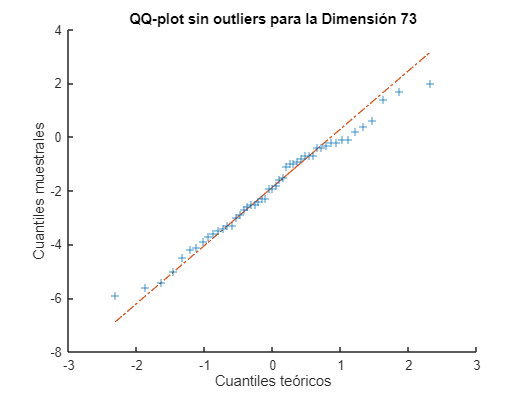

Dimensión 74: 1 outliers encontrados.


col_clean = 49×1
   -2.5000
   -1.2000
         0
    1.0000
   -2.1000
   -1.3000
   -2.6000
   -2.6000
   -2.4000
   -2.4000


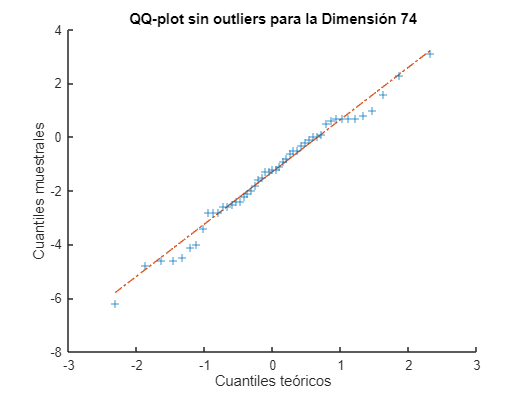

Dimensión 75: 1 outliers encontrados.


col_clean = 49×1
   -0.8000
   -0.7000
    1.0000
    0.9000
   -1.6000
   -0.7000
   -1.0000
   -2.8000
   -1.3000
   -1.6000


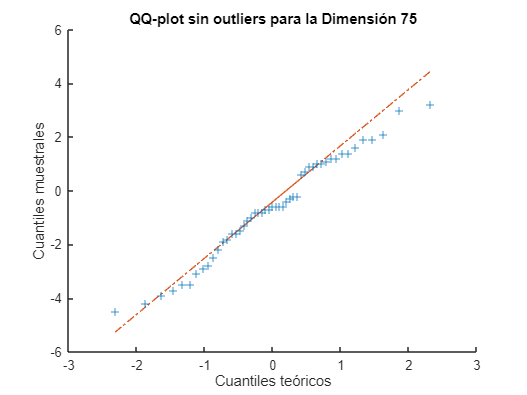

Dimensión 76: 0 outliers encontrados.


col_clean = 50×1
    2.1000
   -1.4000
    1.7000
    2.4000
   -0.4000
    1.6000
    2.3000
   -1.6000
    0.7000
   -1.1000


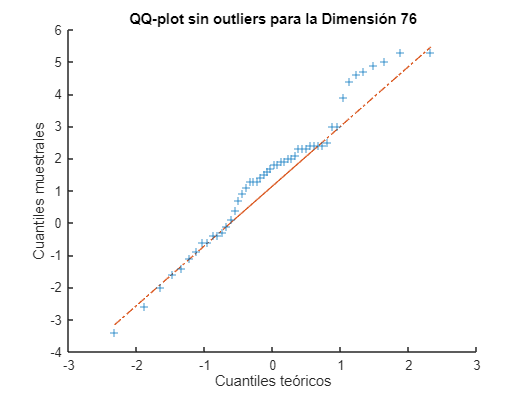

Dimensión 77: 0 outliers encontrados.


col_clean = 50×1
   -5.4000
   -1.0000
   -2.5000
   -5.6000
    0.2000
   -3.5000
   -3.2000
  -10.3000
   -6.6000
   -9.8000


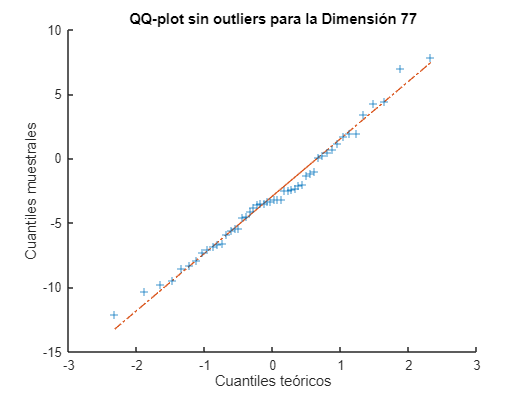

Dimensión 78: 1 outliers encontrados.


col_clean = 49×1
   -1.7000
    1.2000
   -2.8000
   -5.7000
    1.3000
    0.2000
   -1.0000
   -5.7000
   -4.7000
   -9.3000


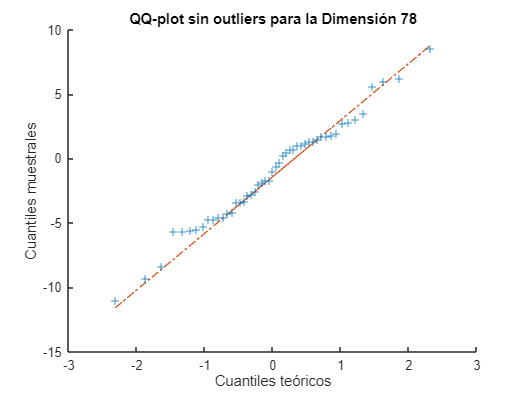

Dimensión 79: 2 outliers encontrados.


col_clean = 48×1
    0.8000
    4.3000
    0.4000
   -2.0000
    3.1000
    5.7000
    1.5000
   -1.8000
   -0.6000
   -6.5000


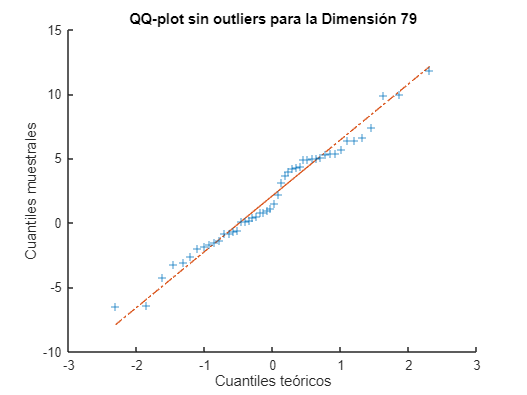

Dimensión 80: 2 outliers encontrados.


col_clean = 48×1
    0.6000
    4.2000
    2.7000
         0
    2.5000
    6.5000
    1.8000
    2.9000
    1.5000
   -6.3000


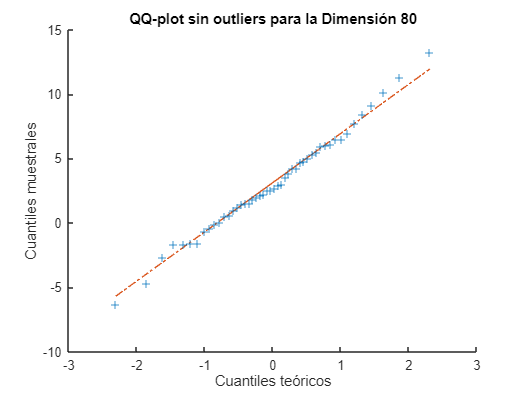

Dimensión 81: 0 outliers encontrados.


col_clean = 50×1
   -1.5000
    2.6000
    2.9000
   -0.1000
    2.0000
    3.2000
    0.1000
   -0.3000
    2.0000
   -6.5000


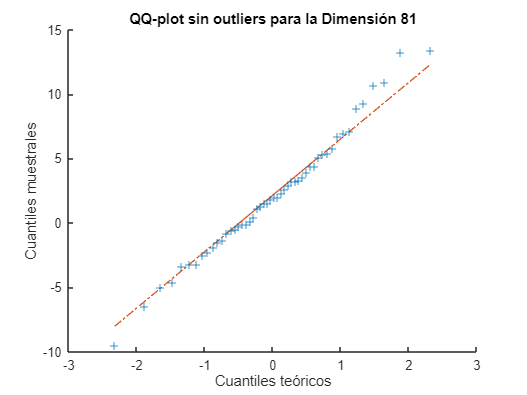

Dimensión 82: 0 outliers encontrados.


col_clean = 50×1
   -0.6000
  -22.8000
  -34.0000
  -22.7000
  -33.1000
  -45.6000
  -11.6000
   15.4000
  -37.8000
  -45.0000


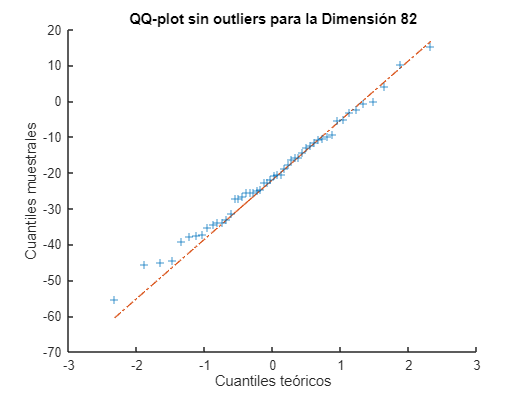

Dimensión 83: 0 outliers encontrados.


col_clean = 50×1
   -1.8000
  -24.5000
  -35.8000
  -25.9000
  -29.8000
  -42.9000
  -14.1000
   15.6000
  -35.3000
  -43.8000


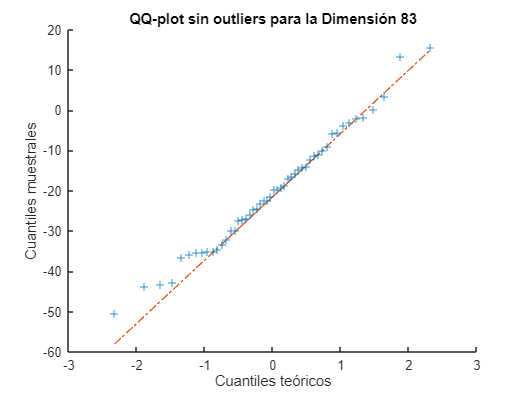

Dimensión 84: 0 outliers encontrados.


col_clean = 50×1
   -1.2000
  -24.4000
  -34.9000
  -23.9000
  -29.9000
  -44.7000
  -12.1000
   13.2000
  -36.3000
  -44.5000


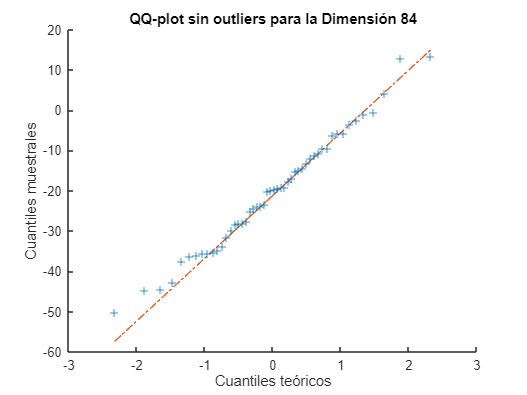

Dimensión 85: 0 outliers encontrados.


col_clean = 50×1
   -1.2000
  -24.3000
  -36.9000
  -24.3000
  -30.8000
  -43.3000
   -9.9000
   11.8000
  -35.7000
  -47.7000


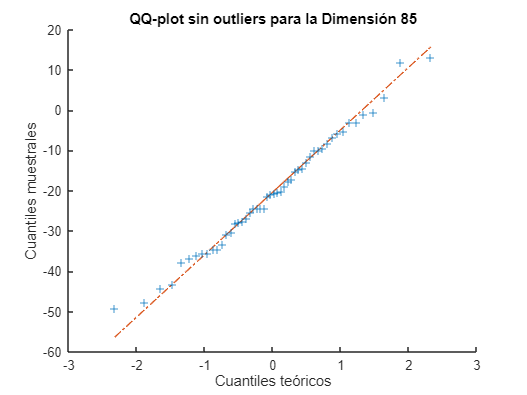

Dimensión 86: 0 outliers encontrados.


col_clean = 50×1
    1.2000
  -25.3000
  -37.8000
  -25.7000
  -29.3000
  -42.8000
   -9.5000
   12.6000
  -34.5000
  -46.7000


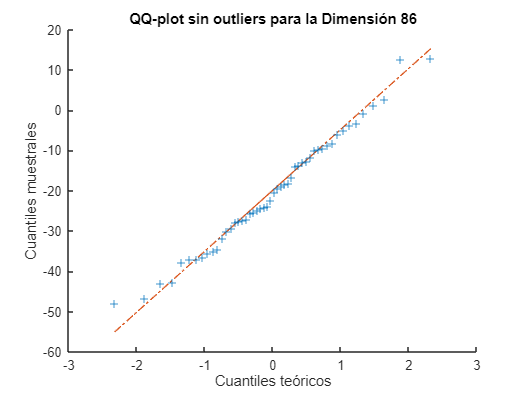

Dimensión 87: 2 outliers encontrados.


col_clean = 48×1
   49.0000
   37.2100
    0.0900
   49.0000
   50.4100
    1.9600
    2.5600
   24.0100
    0.3600
    2.5600


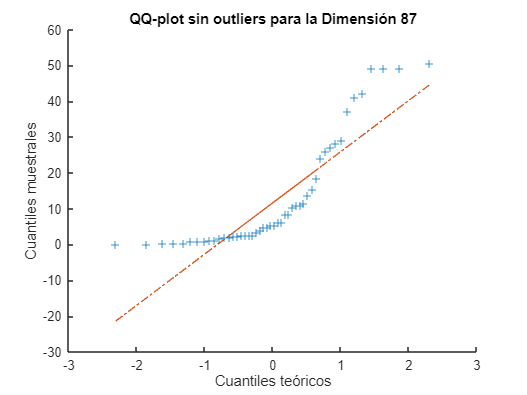

Dimensión 88: 3 outliers encontrados.


col_clean = 47×1
   24.0100
   15.2100
         0
   14.4400
    2.2500
    1.6900
   16.8100
    1.6900
    9.6100
    0.0400


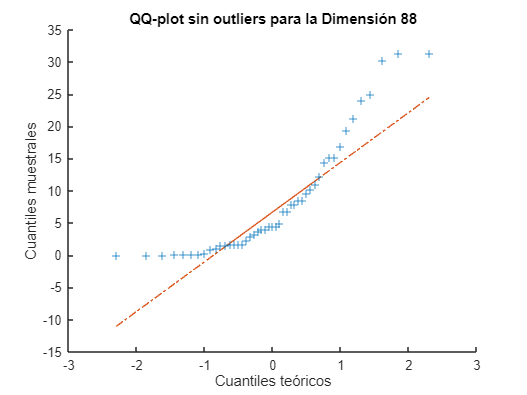

Dimensión 89: 5 outliers encontrados.


col_clean = 45×1
   32.4900
  108.1600
    8.4100
   13.6900
   26.0100
   19.3600
   60.8400
   36.0000
   72.2500
   15.2100


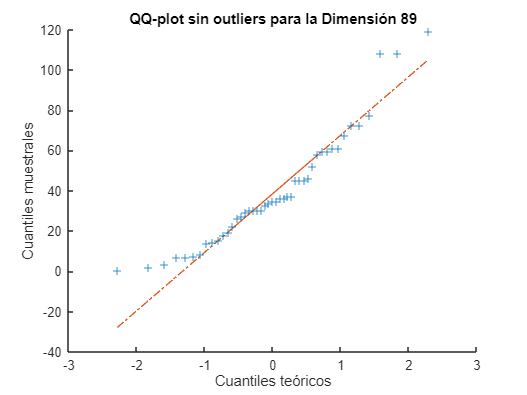

Dimensión 90: 2 outliers encontrados.


col_clean = 48×1
  331.2400
  184.9600
  184.9600
   57.7600
   84.6400
  169.0000
   62.4100
  187.6900
  222.0100
  299.2900


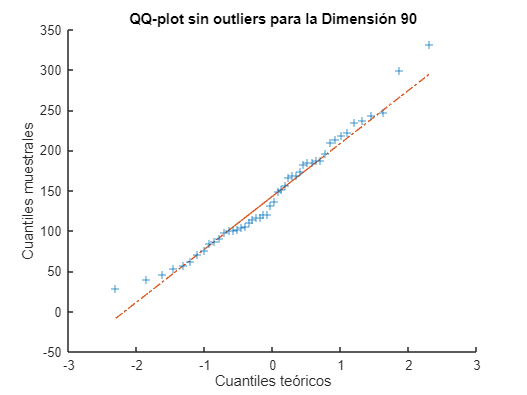

Dimensión 91: 1 outliers encontrados.


col_clean = 49×1
   42.2500
   38.4400
   20.2500
  127.6900
  141.6100
   39.6900
  169.0000
   86.4900
   20.2500
   12.2500


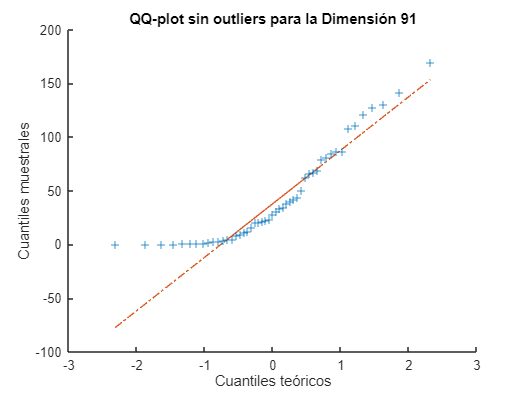

Dimensión 92: 5 outliers encontrados.


col_clean = 45×1
  123.2100
  106.0900
   92.1600
  158.7600
   34.8100
   28.0900
   90.2500
    3.6100
   56.2500
   19.3600


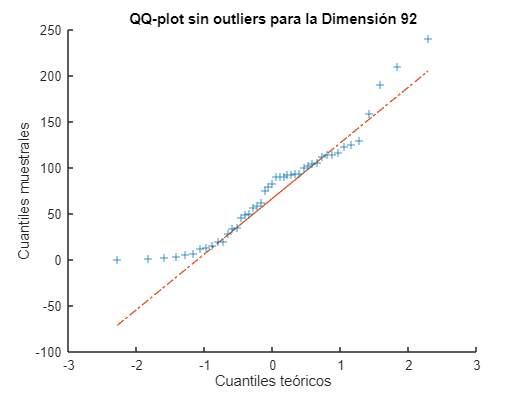

Dimensión 93: 5 outliers encontrados.


col_clean = 45×1
   62.4100
   50.4100
    6.7600
  127.6900
    4.0000
    0.3600
   44.8900
    5.2900
    5.2900
    0.1600


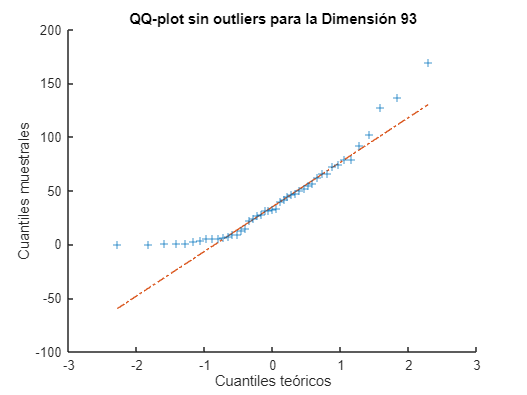

Dimensión 94: 6 outliers encontrados.


col_clean = 44×1
   90.2500
   56.2500
   20.2500
  163.8400
    3.6100
    2.8900
   38.4400
    5.2900
   16.0000
    0.8100


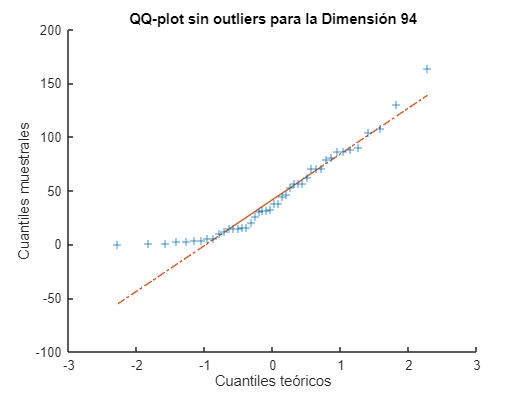

Dimensión 95: 2 outliers encontrados.


col_clean = 48×1
  116.6400
  116.6400
   21.1600
  231.0400
    1.0000
   21.1600
   31.3600
    9.0000
   26.0100
    1.0000


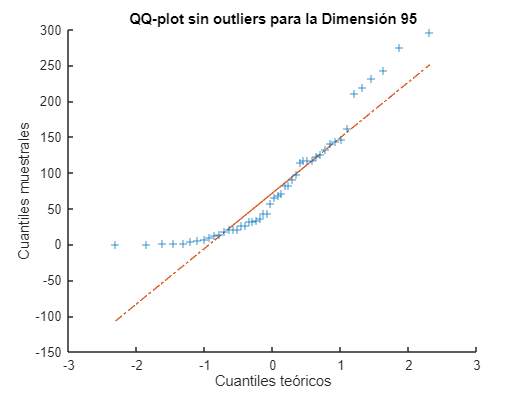

Dimensión 96: 2 outliers encontrados.


col_clean = 48×1
   36.0000
   19.3600
   12.2500
   60.8400
  100.0000
    5.2900
    0.0100
    1.9600
    0.0900
   23.0400


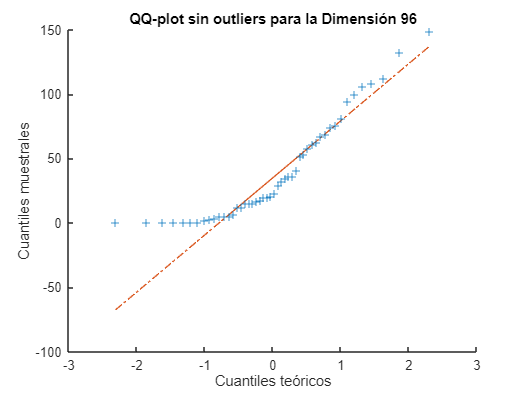

Dimensión 97: 5 outliers encontrados.


col_clean = 45×1
   40.9600
         0
    9.6100
   16.8100
   10.8900
   28.0900
   17.6400
   94.0900
    0.1600
   39.6900


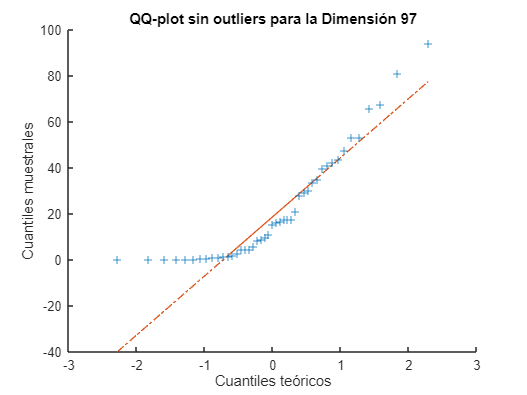

Dimensión 98: 3 outliers encontrados.


col_clean = 47×1
  182.2500
   27.0400
  139.2400
  193.2100
    0.0400
  123.2100
  176.8900
  144.0000
  259.2100
  327.6100


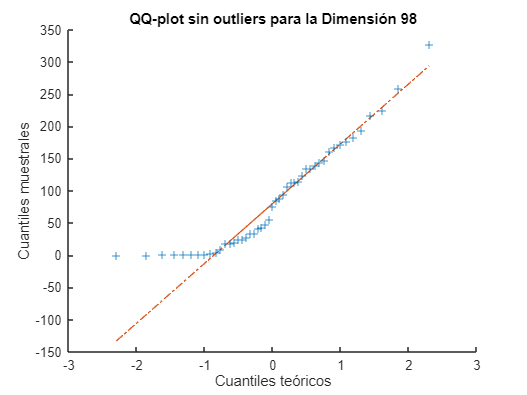

Dimensión 99: 3 outliers encontrados.


col_clean = 47×1
  129.9600
    4.8400
    4.4100
    4.4100
   22.0900
   14.4400
   67.2400
  114.4900
   73.9600
  136.8900


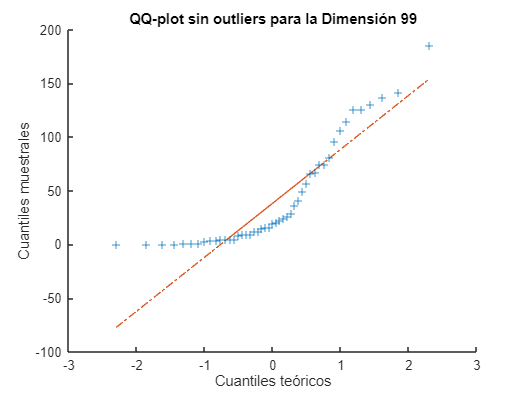

Dimensión 100: 3 outliers encontrados.


col_clean = 47×1
  174.2400
    9.6100
    0.1600
   53.2900
   23.0400
    1.2100
   30.2500
   92.1600
   38.4400
   96.0400


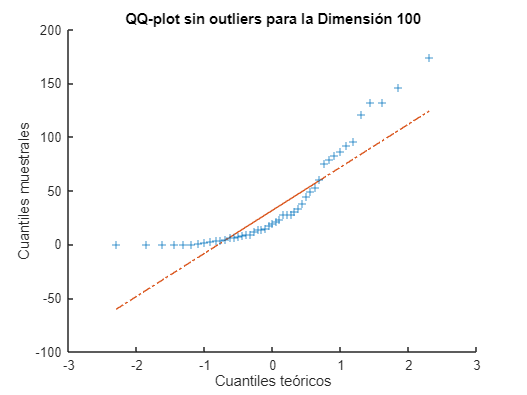

Dimensión 101: 0 outliers encontrados.


col_clean = 50×1
1.0e+03 *

    1.3988
    0.9734
    0.9364
    0.4244
    0.5760
    1.4900
    1.1492
    1.4213
    1.1696
    1.3177


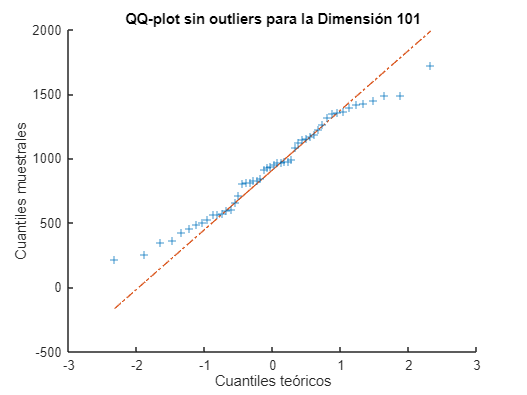

Dimensión 102: 5 outliers encontrados.


col_clean = 45×1
    8.4100
    0.4900
   21.1600
    4.8400
   13.6900
    3.2400
    2.8900
    0.3600
    1.0000
    1.0000


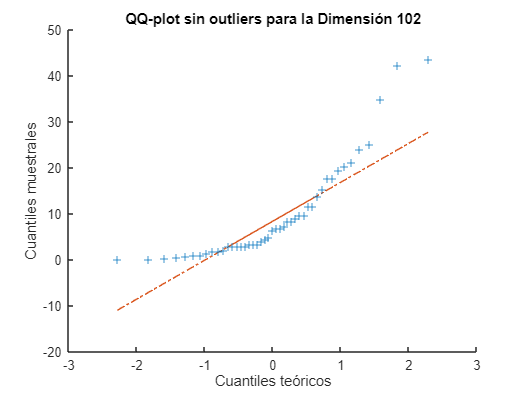

Dimensión 103: 4 outliers encontrados.


col_clean = 46×1
    4.4100
    4.4100
    5.2900
   17.6400
   31.3600
    4.4100
   12.9600
   22.0900
    0.4900
    7.2900


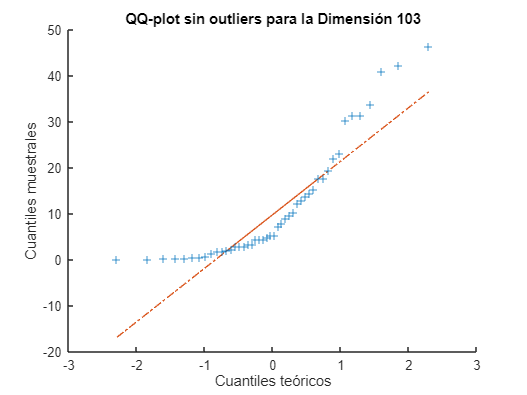

Dimensión 104: 4 outliers encontrados.


col_clean = 46×1
    4.8400
    7.8400
   11.5600
   33.6400
   20.2500
    1.0000
    3.6100
   21.1600
    6.2500
    1.4400


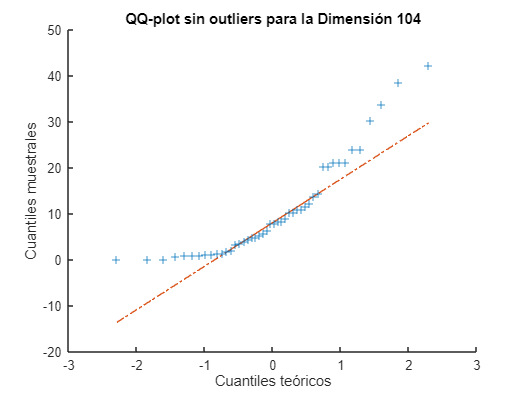

Dimensión 105: 5 outliers encontrados.


col_clean = 45×1
   15.2100
    1.0000
   10.8900
    7.2900
   17.6400
    2.8900
         0
   21.1600
    2.8900
    0.0100


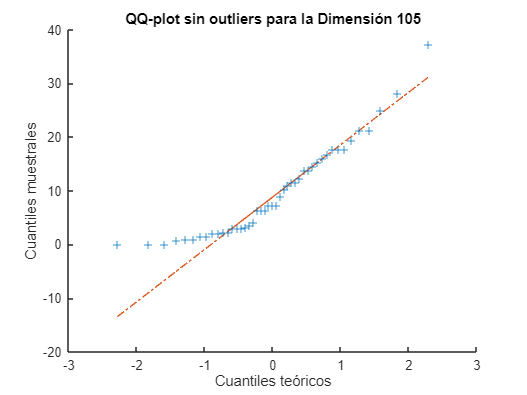

Dimensión 106: 0 outliers encontrados.


col_clean = 50×1
   59.2900
   90.2500
    0.4900
   20.2500
   25.0000
    0.2500
    5.7600
  108.1600
    9.6100
   62.4100


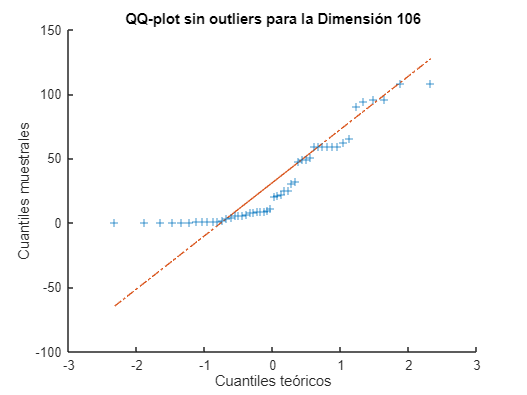

Dimensión 107: 2 outliers encontrados.


col_clean = 48×1
   33.6400
  278.8900
   90.2500
  176.8900
  475.2400
   11.5600
    0.0100
  207.3600
    0.3600
    7.2900


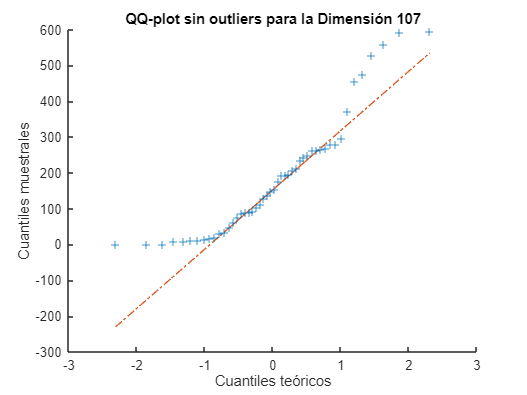

Dimensión 108: 3 outliers encontrados.


col_clean = 47×1
   51.8400
  256.0000
   38.4400
  225.0000
  479.6100
    1.6900
   51.8400
  213.1600
    6.2500
    0.8100


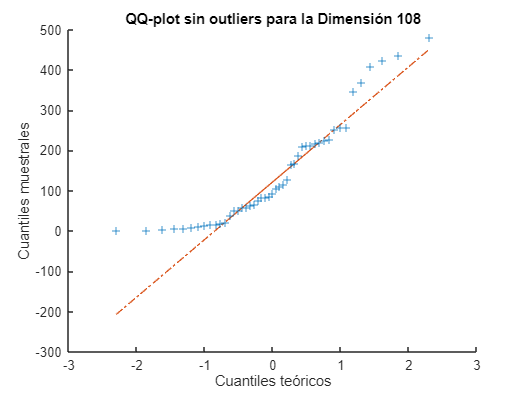

Dimensión 109: 2 outliers encontrados.


col_clean = 48×1
   33.6400
  272.2500
  129.9600
  146.4100
  566.4400
    1.6900
   15.2100
  201.6400
    0.8100
    1.9600


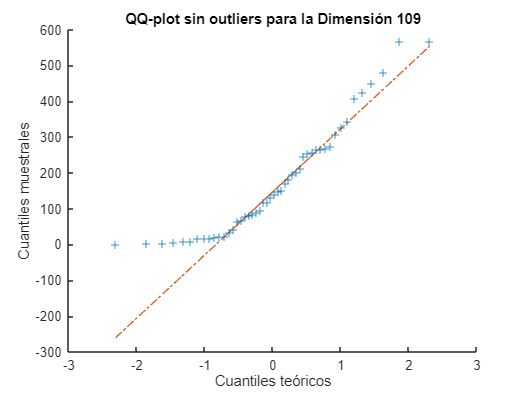

Dimensión 110: 1 outliers encontrados.


col_clean = 49×1
   37.2100
  249.6400
  139.2400
   77.4400
  571.2100
    3.6100
   24.0100
  228.0100
    1.2100
    9.0000


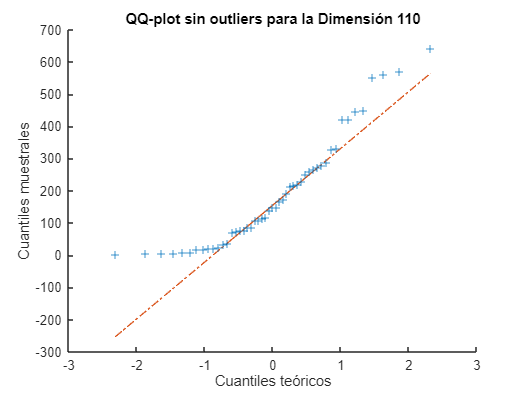

Dimensión 111: 7 outliers encontrados.


col_clean = 43×1
   96.0400
  151.2900
   23.0400
   81.0000
  210.2500
  104.0400
   86.4900
   44.8900
    1.4400
   20.2500


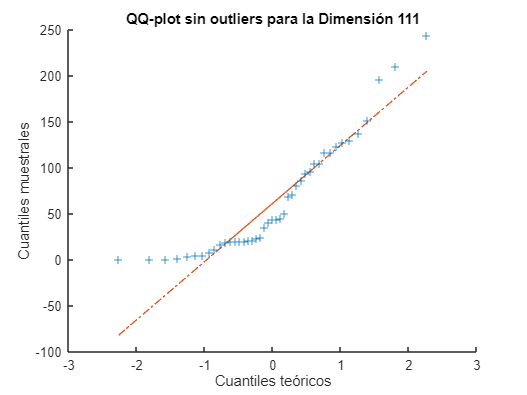

Dimensión 112: 3 outliers encontrados.


col_clean = 47×1
1.0e+03 *

    1.6484
    0.9548
    0.6200
    1.0693
    0.2250
    0.6150
    1.3764
    0.5856
    0.7398
    1.5761


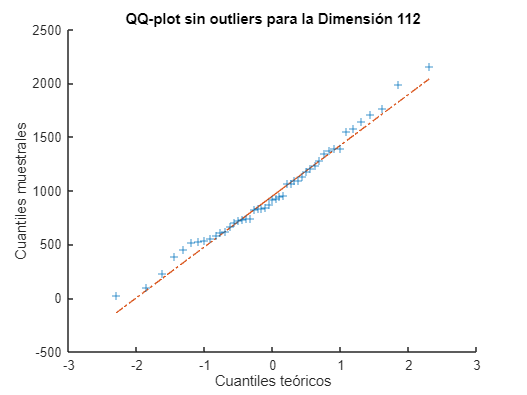

Dimensión 113: 3 outliers encontrados.


col_clean = 47×1
1.0e+03 *

    1.1156
    0.2690
    0.2958
    0.5108
    0.0040
    0.0960
    0.6002
    1.1222
    0.0828
    0.5808


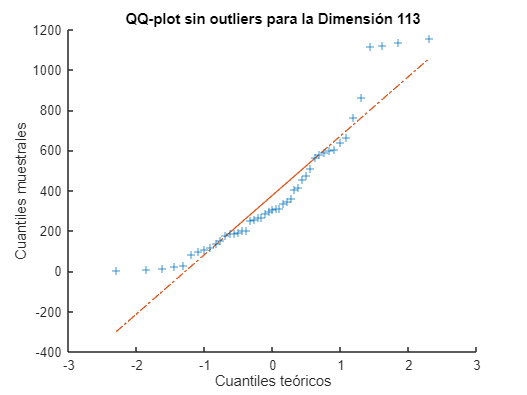

Dimensión 114: 5 outliers encontrados.


col_clean = 45×1
  432.6400
   44.8900
    1.0000
   10.8900
  141.6100
   21.1600
  125.4400
    4.4100
   65.6100
  424.3600


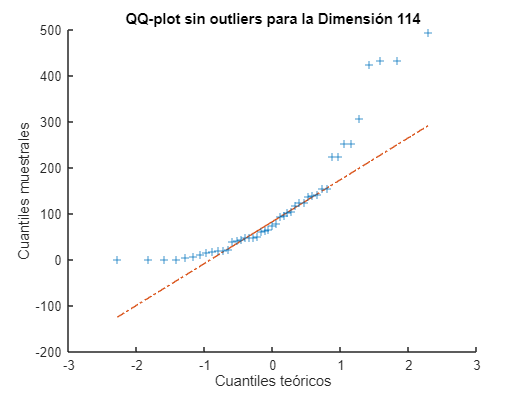

Dimensión 115: 2 outliers encontrados.


col_clean = 48×1
   92.1600
   14.4400
  313.2900
  345.9600
  412.0900
  342.2500
   10.8900
   67.2400
  116.6400
   32.4900


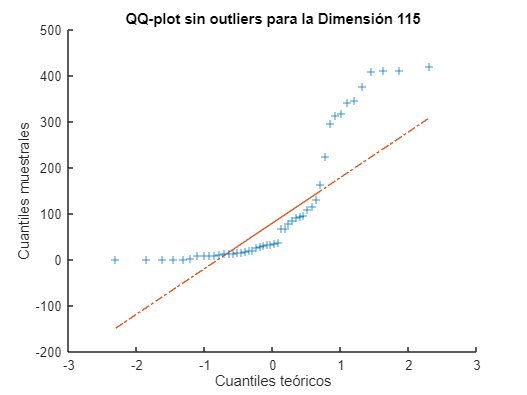

Dimensión 116: 4 outliers encontrados.


col_clean = 46×1
  108.1600
    0.2500
  182.2500
  309.7600
  345.9600
  146.4100
    1.0000
  424.3600
   75.6900
   33.6400


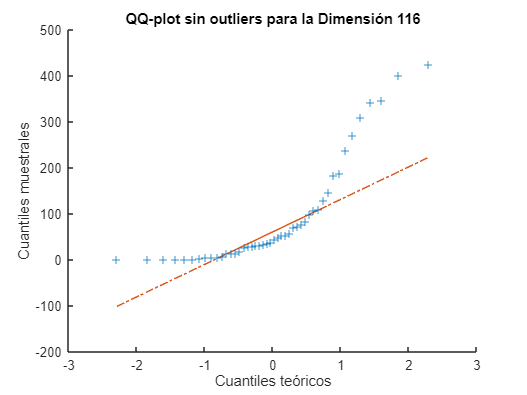

Dimensión 117: 4 outliers encontrados.


col_clean = 46×1
    1.0000
    2.5600
   17.6400
    0.6400
   47.6100
   39.6900
    0.0900
   46.2400
    5.7600
    9.0000


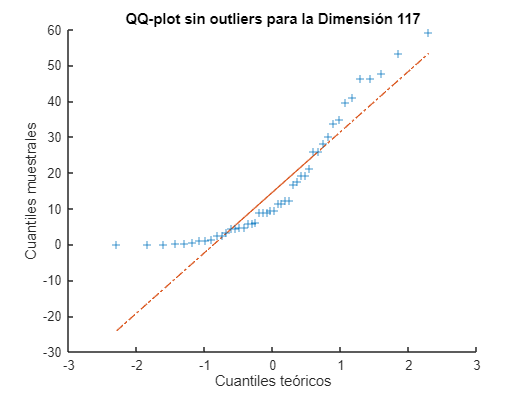

Dimensión 118: 3 outliers encontrados.


col_clean = 47×1
   47.6100
   59.2900
   98.0100
   31.3600
  136.8900
    4.0000
   32.4900
   10.8900
  108.1600
  110.2500


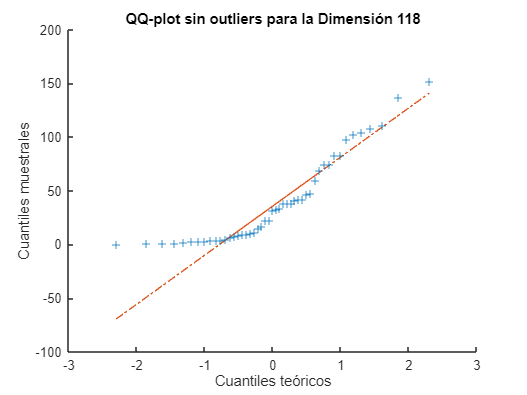

Dimensión 119: 2 outliers encontrados.


col_clean = 48×1
   43.5600
   16.8100
   75.6900
  104.0400
   32.4900
   25.0000
    0.2500
   15.2100
    6.7600
   65.6100


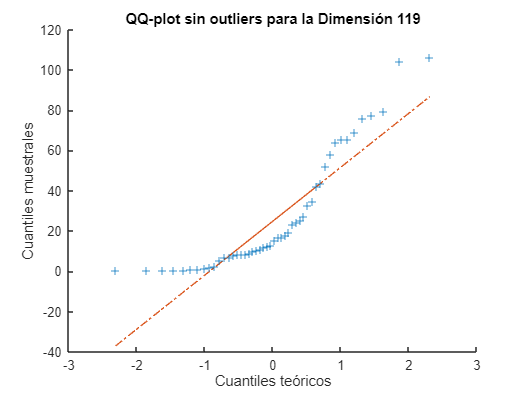

Dimensión 120: 3 outliers encontrados.


col_clean = 47×1
   47.6100
   17.6400
   47.6100
   32.4900
   15.2100
   12.9600
    6.2500
    1.6900
   19.3600
   16.8100


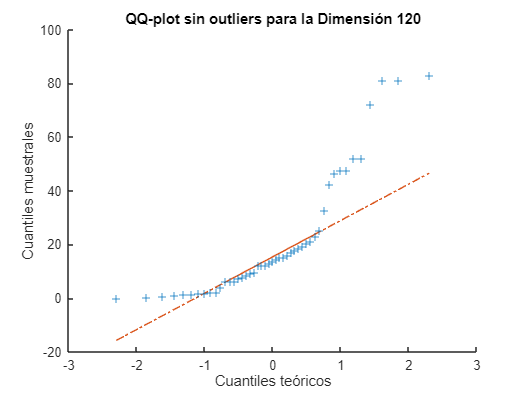

Dimensión 121: 4 outliers encontrados.


col_clean = 46×1
    1.2100
   29.1600
   15.2100
   13.6900
    1.4400
   26.0100
   54.7600
    0.6400
   10.8900
    1.9600


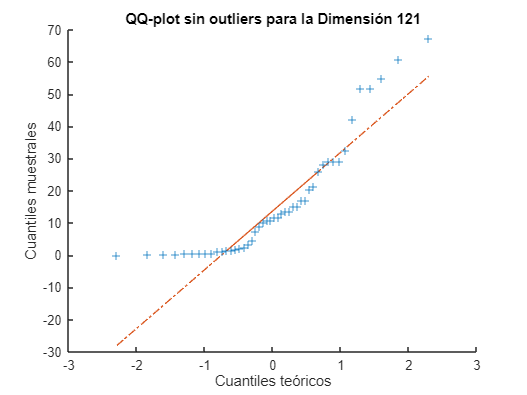

Dimensión 122: 5 outliers encontrados.


col_clean = 45×1
  129.9600
  148.8400
    2.2500
    8.4100
   49.0000
   92.1600
  219.0400
    6.2500
   11.5600
    1.0000


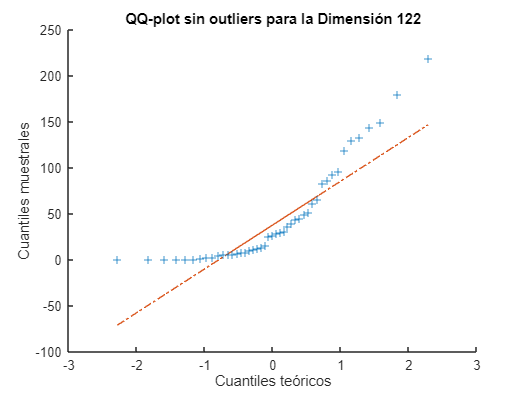

Dimensión 123: 2 outliers encontrados.


col_clean = 48×1
  153.7600
  163.8400
   32.4900
   38.4400
  171.6100
   57.7600
   98.0100
  184.9600
  139.2400
   46.2400


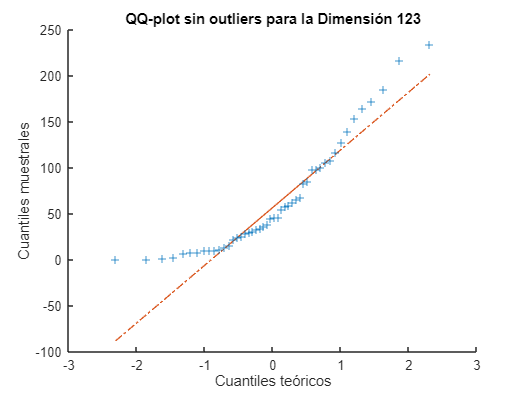

Dimensión 124: 3 outliers encontrados.


col_clean = 47×1
   94.0900
    7.2900
  118.8100
  134.5600
   11.5600
   51.8400
   96.0400
   22.0900
   20.2500
    1.2100


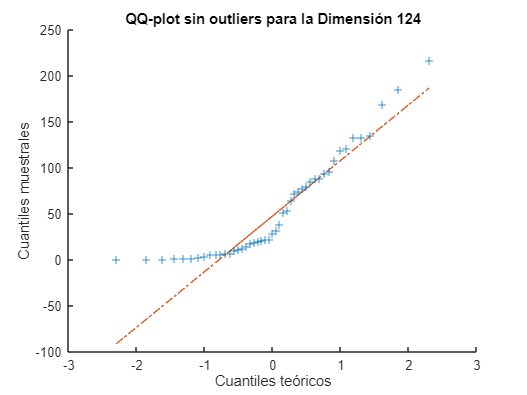

Dimensión 125: 5 outliers encontrados.


col_clean = 45×1
   81.0000
    5.2900
  139.2400
    0.4900
    9.6100
   54.7600
   82.8100
   46.2400
    2.8900
   21.1600


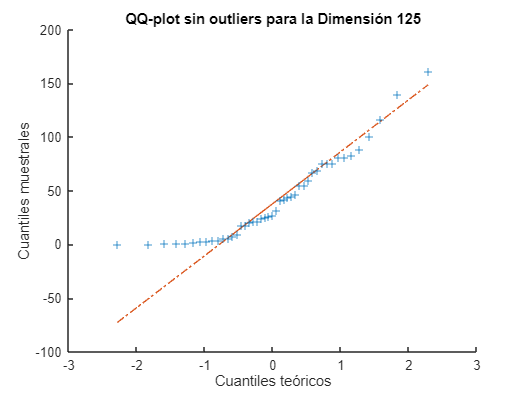

Dimensión 126: 5 outliers encontrados.


col_clean = 45×1
  104.0400
    2.5600
   90.2500
    8.4100
   47.6100
   34.8100
   32.4900
  108.1600
    0.1600
   43.5600


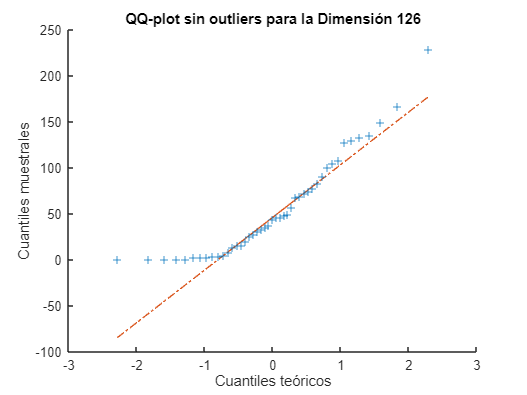

Dimensión 127: 2 outliers encontrados.


col_clean = 48×1
  345.9600
  102.0100
   11.5600
  110.2500
   16.8100
    0.0900
  176.8900
  400.0000
    7.8400
   28.0900


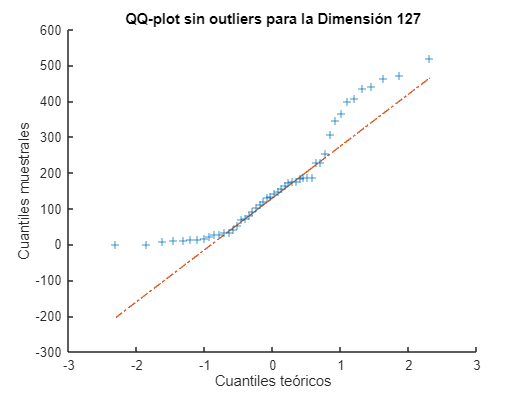

Dimensión 128: 1 outliers encontrados.


col_clean = 49×1
  361.0000
   59.2900
    4.0000
   60.8400
    4.8400
    0.0400
  118.8100
  380.2500
   10.2400
   33.6400


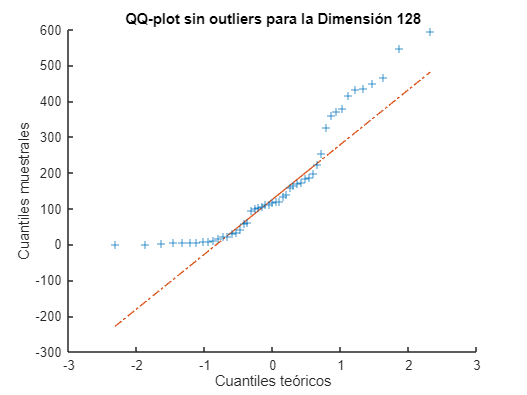

Dimensión 129: 1 outliers encontrados.


col_clean = 49×1
  324.0000
   98.0100
    5.7600
   98.0100
    4.0000
    0.0400
  146.4100
  396.0100
    7.2900
   27.0400


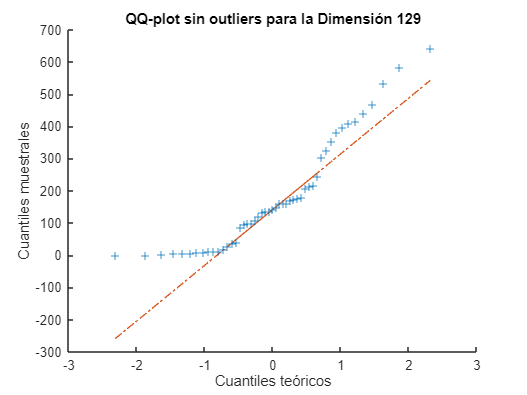

Dimensión 130: 1 outliers encontrados.


col_clean = 49×1
  292.4100
  116.6400
    0.1600
   90.2500
    3.2400
    1.0000
  207.3600
  445.2100
   10.8900
   10.8900


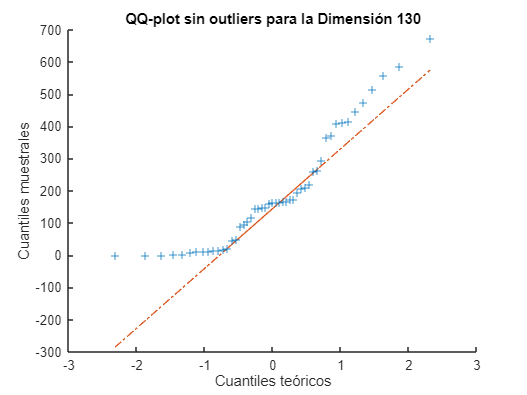

Dimensión 131: 2 outliers encontrados.


col_clean = 48×1
  262.4400
   86.4900
    0.2500
   56.2500
    9.0000
    0.8100
  179.5600
  392.0400
    3.6100
   19.3600


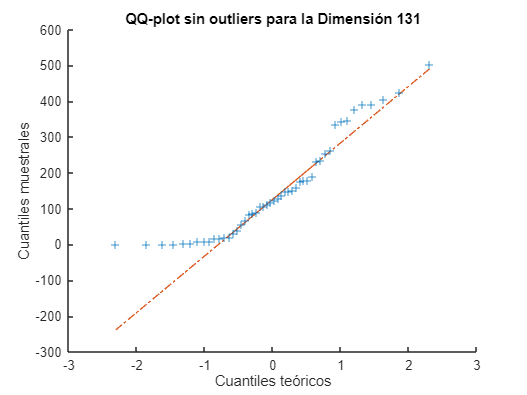

Dimensión 132: 4 outliers encontrados.


col_clean = 46×1
    0.0900
    0.0400
    0.0400
    0.8100
    0.2500
    2.2500
    6.7600
    5.7600
    1.0000
    2.5600


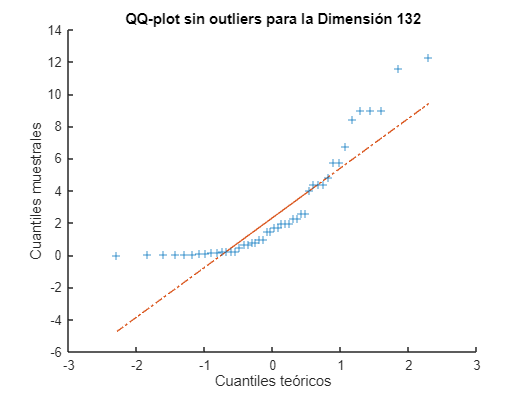

Dimensión 133: 6 outliers encontrados.


col_clean = 44×1
   10.8900
    5.7600
   14.4400
   10.8900
    7.2900
    3.6100
    4.8400
    0.0400
    2.5600
    5.7600


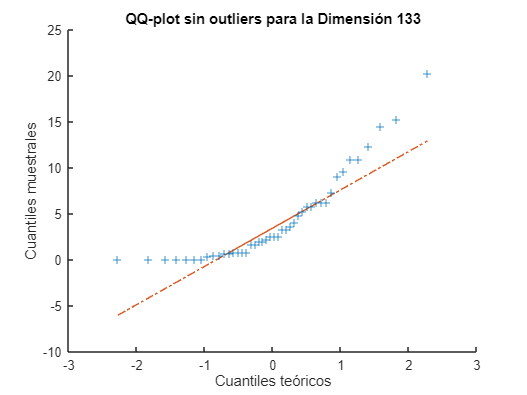

Dimensión 134: 2 outliers encontrados.


col_clean = 48×1
    0.0400
    0.0900
    2.8900
    0.0100
    0.4900
    0.0400
    5.7600
   15.2100
    2.5600
    3.6100


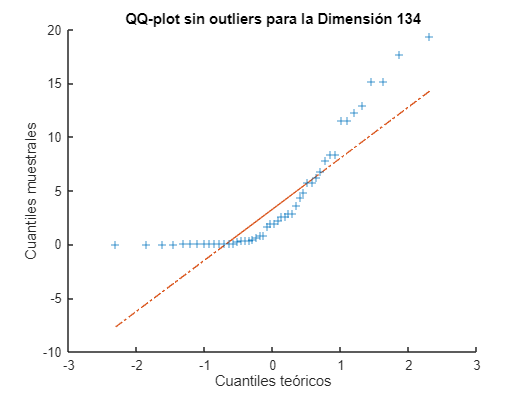

Dimensión 135: 4 outliers encontrados.


col_clean = 46×1
    0.0400
    0.2500
    2.2500
    0.8100
    0.2500
    0.8100
   13.6900
    2.8900
    0.4900
    0.0400


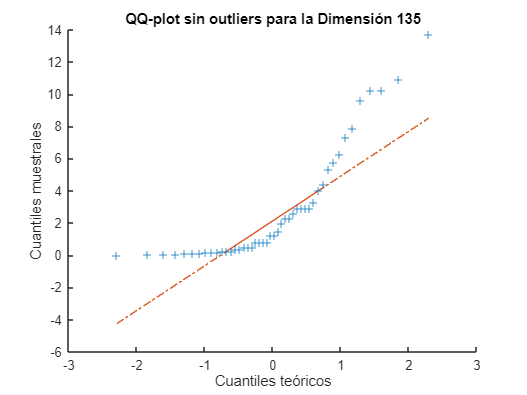

Dimensión 136: 3 outliers encontrados.


col_clean = 47×1
   19.3600
   16.0000
    0.4900
    9.6100
    1.0000
   16.8100
   15.2100
   11.5600
    4.0000
    9.6100


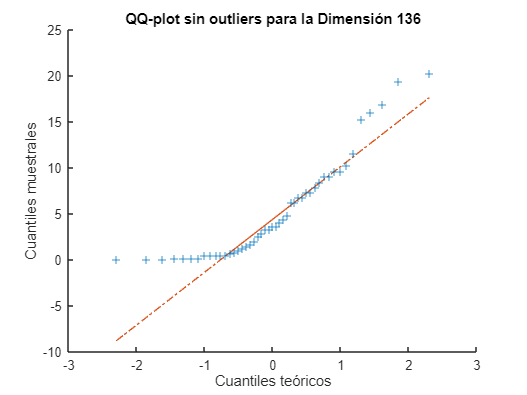

Dimensión 137: 3 outliers encontrados.


col_clean = 47×1
    6.2500
    4.4100
    1.9600
   34.8100
   16.8100
    7.2900
   24.0100
   23.0400
    2.8900
    8.4100


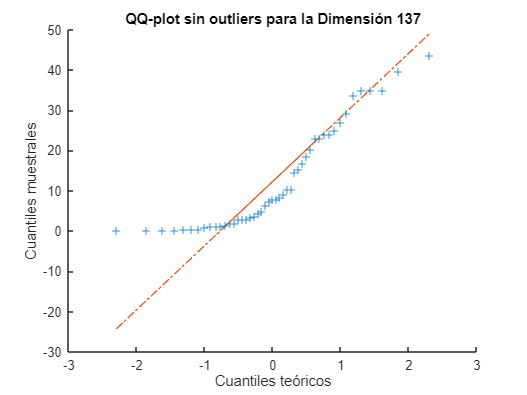

Dimensión 138: 3 outliers encontrados.


col_clean = 47×1
    8.4100
    4.4100
    2.5600
   40.9600
    0.0400
    0.0400
   19.3600
    6.7600
    1.2100
    0.0400


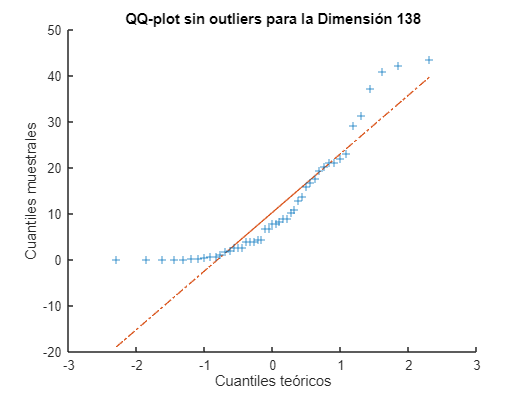

Dimensión 139: 5 outliers encontrados.


col_clean = 45×1
    1.2100
    9.6100
    0.8100
   21.1600
    6.2500
   29.1600
    0.1600
    2.2500
   10.2400
    4.0000


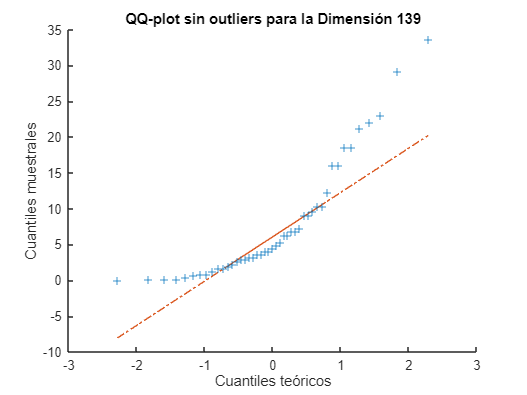

Dimensión 140: 3 outliers encontrados.


col_clean = 47×1
    5.7600
    9.0000
   13.6900
    4.8400
    0.0400
   18.4900
    9.6100
   22.0900
    0.2500
    5.2900


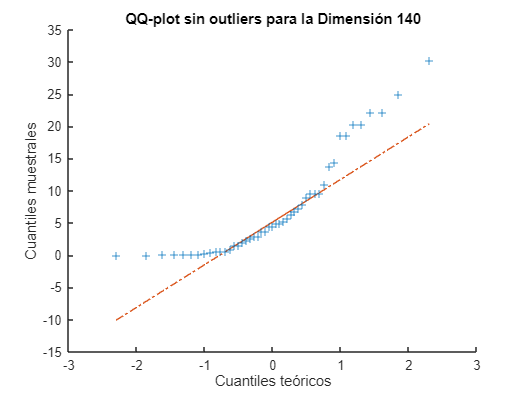

Dimensión 141: 3 outliers encontrados.


col_clean = 47×1
   29.1600
    6.2500
   11.5600
   12.2500
    7.2900
    9.6100
   32.4900
   19.3600
   44.8900
    0.6400


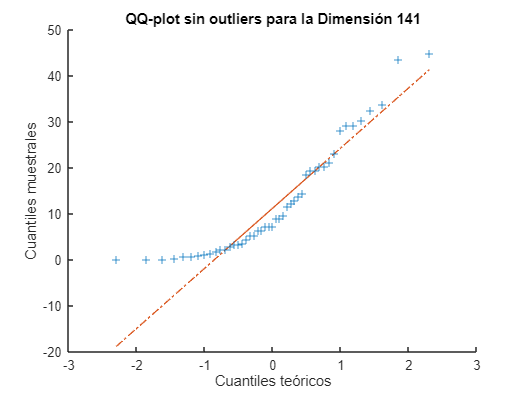

Dimensión 142: 2 outliers encontrados.


col_clean = 48×1
   16.0000
    6.2500
    0.0100
   22.0900
    1.2100
    0.3600
    2.5600
    0.0900
   43.5600
   40.9600


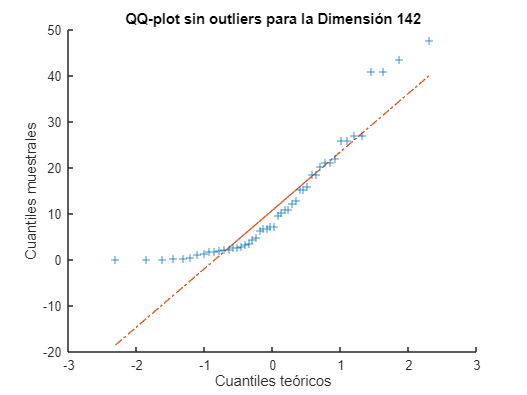

Dimensión 143: 5 outliers encontrados.


col_clean = 45×1
   31.3600
    4.8400
   16.0000
    0.0900
   17.6400
   31.3600
    5.2900
   10.8900
   19.3600
   64.0000


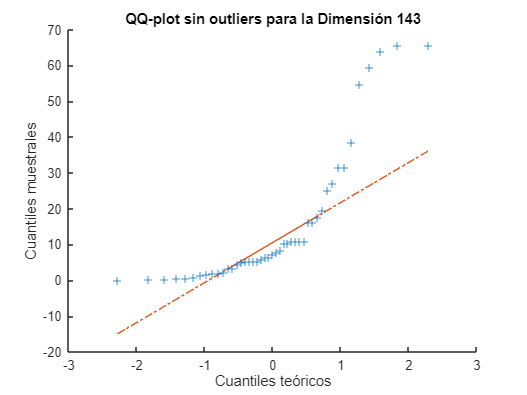

Dimensión 144: 3 outliers encontrados.


col_clean = 47×1
   31.3600
    1.9600
    0.0400
    4.4100
    6.2500
    1.0000
    0.0900
   30.2500
    1.4400
   31.3600


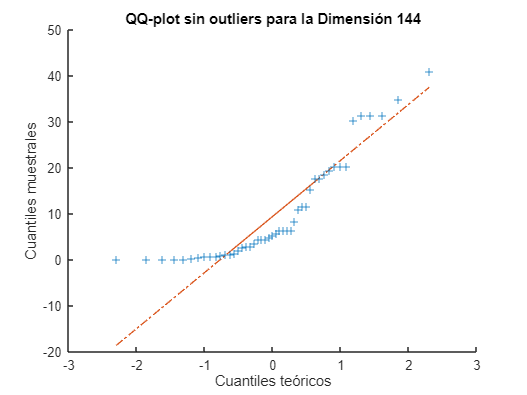

Dimensión 145: 0 outliers encontrados.


col_clean = 50×1
    4.8400
    0.0100
    0.4900
   15.2100
   10.2400
    6.2500
   31.3600
   60.8400
    0.0900
   10.2400


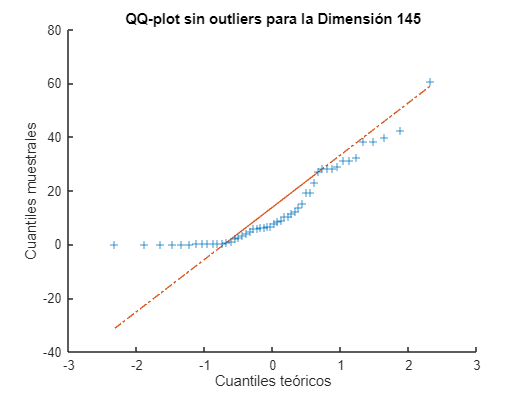

Dimensión 146: 3 outliers encontrados.


col_clean = 47×1
   24.0100
    5.2900
   13.6900
   53.2900
   34.8100
   57.7600
   73.9600
   17.6400
    0.0100
    3.6100


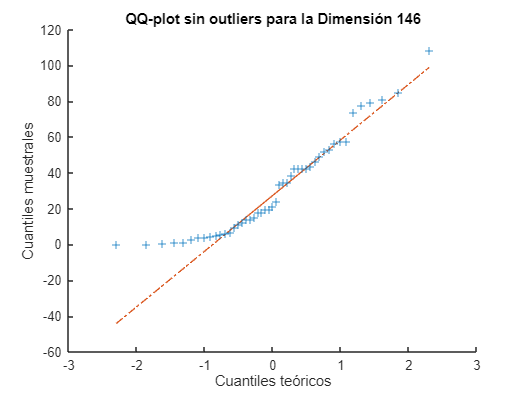

Dimensión 147: 3 outliers encontrados.


col_clean = 47×1
   14.4400
    7.2900
   21.1600
   34.8100
   13.6900
   34.8100
  106.0900
   54.7600
    1.0000
    0.8100


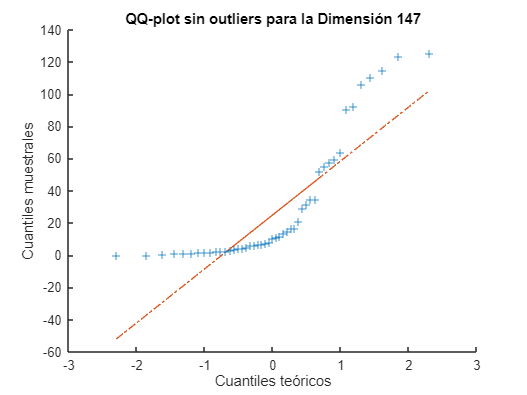

Dimensión 148: 6 outliers encontrados.


col_clean = 44×1
    3.6100
    8.4100
   19.3600
   30.2500
   12.9600
   60.8400
   39.6900
    0.0100
   19.3600
   70.5600


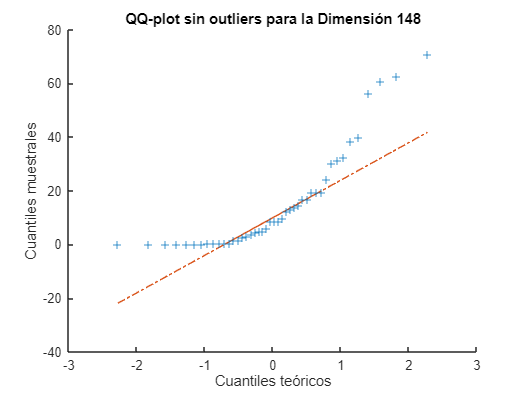

Dimensión 149: 4 outliers encontrados.


col_clean = 46×1
    6.7600
    1.2100
    1.0000
    3.2400
   40.9600
   54.7600
    0.8100
    4.0000
   84.6400
   25.0000


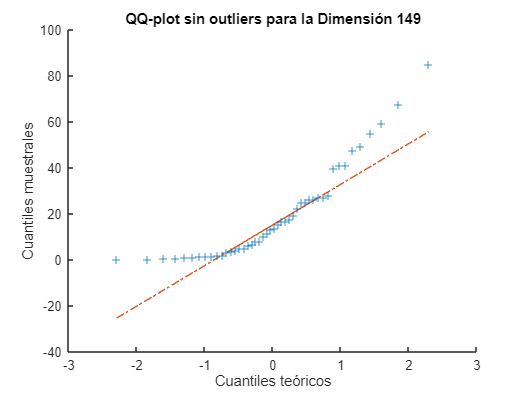

Dimensión 150: 1 outliers encontrados.


col_clean = 49×1
  139.2400
   32.4900
    1.6900
   31.3600
         0
   96.0400
    1.2100
   21.1600
   27.0400
   34.8100


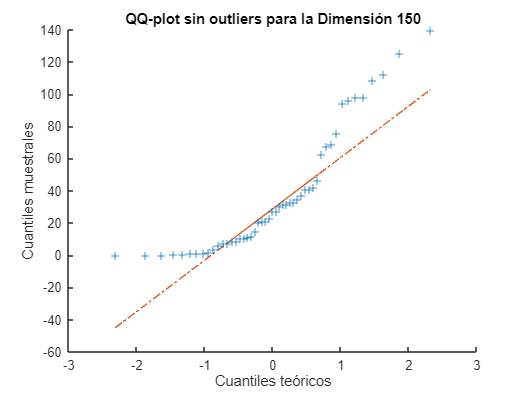

Dimensión 151: 3 outliers encontrados.


col_clean = 47×1
   14.4400
    1.2100
   25.0000
    0.6400
   94.0900
    1.9600
    1.4400
   46.2400
   32.4900
    0.0100


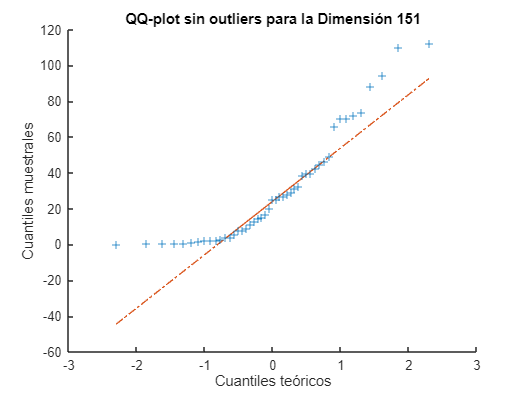

Dimensión 152: 4 outliers encontrados.


col_clean = 46×1
    0.2500
    8.4100
   31.3600
   13.6900
  116.6400
   29.1600
   36.0000
   42.2500
   21.1600
    2.8900


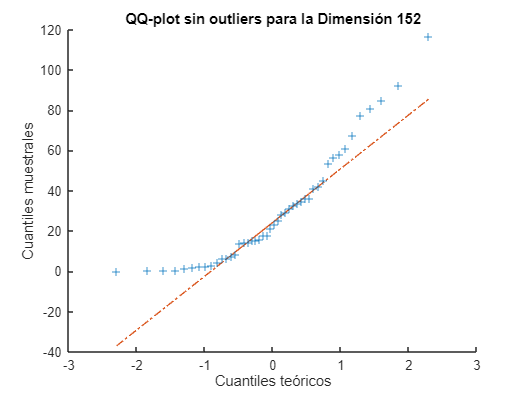

Dimensión 153: 6 outliers encontrados.


col_clean = 44×1
    2.2500
    4.4100
   36.0000
    4.4100
   68.8900
   18.4900
   26.0100
   16.8100
   12.2500
    1.6900


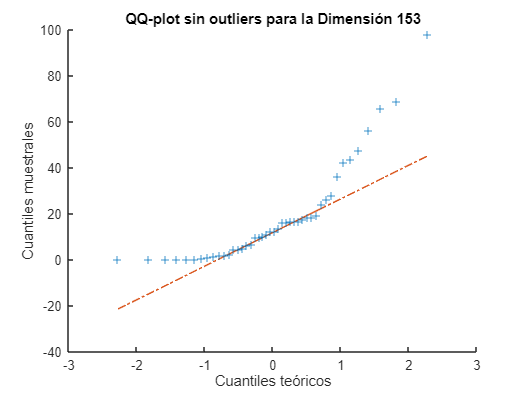

Dimensión 154: 4 outliers encontrados.


col_clean = 46×1
    1.6900
   18.4900
   36.0000
    7.2900
   86.4900
   22.0900
   50.4100
   24.0100
   16.8100
    2.2500


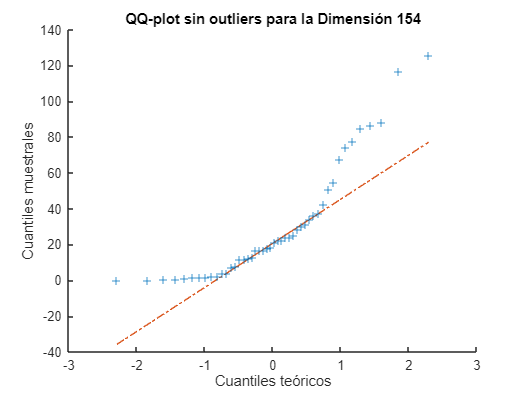

Dimensión 155: 1 outliers encontrados.


col_clean = 49×1
    0.6400
   25.0000
   34.8100
  163.8400
   15.2100
   81.0000
   22.0900
   75.6900
   24.0100
   30.2500


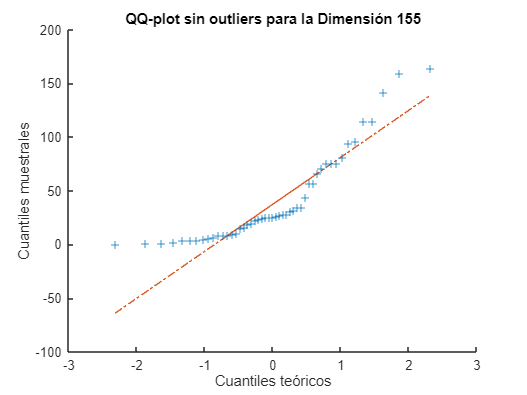

Dimensión 156: 5 outliers encontrados.


col_clean = 45×1
    2.5600
   17.6400
   24.0100
    1.4400
   36.0000
   11.5600
   46.2400
    4.4100
   28.0900
    4.8400


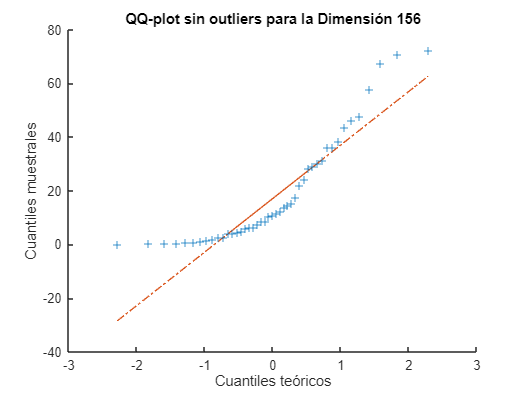

Dimensión 157: 5 outliers encontrados.


col_clean = 45×1
    4.4100
    0.4900
    0.4900
    0.2500
    0.2500
    0.0900
    9.6100
    0.6400
    9.6100
    1.9600


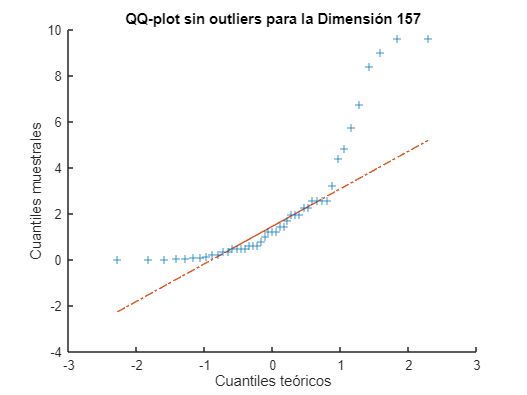

Dimensión 158: 4 outliers encontrados.


col_clean = 46×1
    3.6100
    0.0100
    1.2100
    6.7600
    2.2500
   10.8900
    8.4100
    9.0000
   13.6900
    5.2900


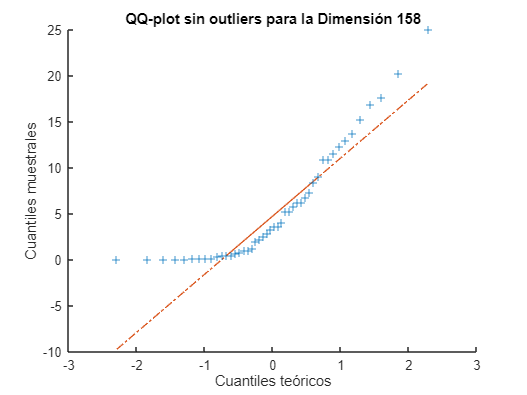

Dimensión 159: 6 outliers encontrados.


col_clean = 44×1
    6.2500
    1.4400
         0
    1.0000
    4.4100
    1.6900
    6.7600
    6.7600
    5.7600
    5.7600


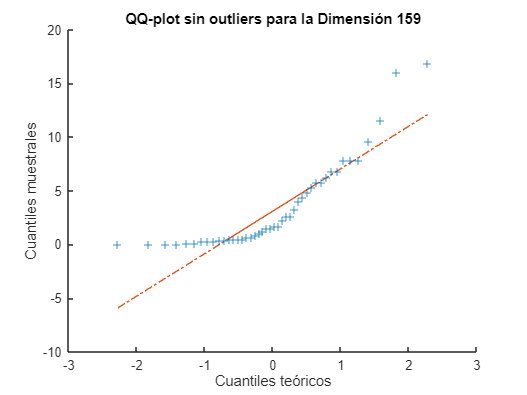

Dimensión 160: 4 outliers encontrados.


col_clean = 46×1
    0.6400
    0.4900
    1.0000
    0.8100
    2.5600
    0.4900
    1.0000
    7.8400
    1.6900
    2.5600


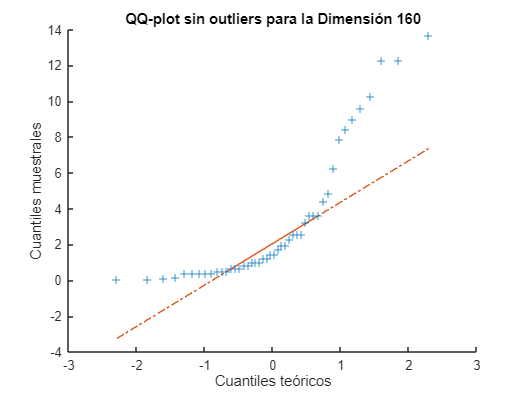

Dimensión 161: 8 outliers encontrados.


col_clean = 42×1
    4.4100
    1.9600
    2.8900
    5.7600
    0.1600
    2.5600
    5.2900
    2.5600
    0.4900
    1.2100


Dimensión 162: 2 outliers encontrados.


col_clean = 48×1
   29.1600
    1.0000
    6.2500
   31.3600
    0.0400
   12.2500
   10.2400
   43.5600
   96.0400
    0.2500


Dimensión 163: 5 outliers encontrados.


col_clean = 45×1
    2.8900
    1.4400
    7.8400
   32.4900
    1.6900
    0.0400
    1.0000
   32.4900
   22.0900
    1.0000


Dimensión 164: 5 outliers encontrados.


col_clean = 45×1
    0.6400
   18.4900
    0.1600
    4.0000
    9.6100
   32.4900
    2.2500
    3.2400
    0.3600
   42.2500


Dimensión 165: 4 outliers encontrados.


col_clean = 46×1
    0.3600
   17.6400
    7.2900
         0
    6.2500
   42.2500
    3.2400
    8.4100
    2.2500
   39.6900


Dimensión 166: 7 outliers encontrados.


col_clean = 43×1
    2.2500
    6.7600
    8.4100
    0.0100
    4.0000
   10.2400
    0.0100
    0.0900
    4.0000
   42.2500


Dimensión 167: 1 outliers encontrados.


col_clean = 49×1
1.0e+03 *

    0.0004
    0.5198
    1.1560
    0.5153
    1.0956
    2.0794
    0.1346
    0.2372
    1.4288
    2.0250


Dimensión 168: 1 outliers encontrados.


col_clean = 49×1
1.0e+03 *

    0.0032
    0.6002
    1.2816
    0.6708
    0.8880
    1.8404
    0.1988
    0.2434
    1.2461
    1.9184


Dimensión 169: 1 outliers encontrados.


col_clean = 49×1
1.0e+03 *

    0.0014
    0.5954
    1.2180
    0.5712
    0.8940
    1.9981
    0.1464
    0.1742
    1.3177
    1.9803


Dimensión 170: 2 outliers encontrados.


col_clean = 48×1
1.0e+03 *

    0.0014
    0.5905
    1.3616
    0.5905
    0.9486
    1.8749
    0.0980
    0.1392
    1.2745
    0.0102


Dimensión 171: 2 outliers encontrados.


col_clean = 48×1
1.0e+03 *

    0.0014
    0.6401
    1.4288
    0.6605
    0.8585
    1.8318
    0.0902
    0.1588
    1.1903
    0.0068


Dimensión 172: 7 outliers encontrados.


col_clean = 43×1
   23.7900
         0
   10.6500
   -1.8200
    6.5600
   -6.3700
   -1.8600
    0.3200
    4.6200
    1.4400


Dimensión 173: 4 outliers encontrados.


col_clean = 46×1
   46.8000
         0
   39.5200
   -4.3500
   -4.8100
  -20.9100
    5.7200
   24.1800
   -1.2000
   28.0500


Dimensión 174: 4 outliers encontrados.


col_clean = 46×1
   77.5200
  141.4400
   22.0400
   34.0400
   66.3000
   34.7600
  106.8600
   89.4000
  147.0500
   39.0000


Dimensión 175: 3 outliers encontrados.


col_clean = 47×1
 -112.8400
  -61.2000
 -153.6800
  -90.4400
  -57.9600
 -169.0000
  -73.4700
  -61.6500
  -52.1500
  -57.0900


Dimensión 176: 6 outliers encontrados.


col_clean = 44×1
   87.6900
   73.1300
   24.9600
  142.3800
  -11.8000
    3.1800
   63.6500
    4.3700
   17.2500
   -1.7600


Dimensión 177: 6 outliers encontrados.


col_clean = 44×1
   75.0500
   53.2500
   11.7000
  144.6400
    3.8000
    1.0200
   41.5400
    5.2900
    9.2000
   -0.3600


Dimensión 178: 4 outliers encontrados.


col_clean = 46×1
  102.6000
   81.0000
   20.7000
  194.5600
    1.9000
    7.8200
   34.7200
    6.9000
   20.4000
    0.9000


Dimensión 179: 4 outliers encontrados.


col_clean = 46×1
   64.8000
   47.5200
  -16.1000
  118.5600
   10.0000
  -10.5800
    0.5600
   -4.2000
   -1.5300
   -4.8000


Dimensión 180: 3 outliers encontrados.


col_clean = 47×1
   86.4000
         0
   36.5800
   56.9900
    0.6600
   58.8300
   55.8600
  116.4000
   -6.4400
  114.0300


Dimensión 181: 3 outliers encontrados.


col_clean = 47×1
  153.9000
   11.4400
   24.7800
   29.1900
   -0.9400
   42.1800
  109.0600
  128.4000
  138.4600
  211.7700


Dimensión 182: 3 outliers encontrados.


col_clean = 47×1
  150.4800
    6.8200
   -0.8400
  -15.3300
   22.5600
   -4.1800
   45.1000
  102.7200
   53.3200
  114.6600


Dimensión 183: 1 outliers encontrados.


col_clean = 49×1
  493.6800
   96.7200
  -12.2400
 -150.3800
 -115.2000
  -42.4600
  186.4500
  720.0700
  328.3200
  225.0600


Dimensión 184: 8 outliers encontrados.


col_clean = 42×1
    6.0900
    1.4700
   10.5800
   12.3200
    7.7700
    6.4800
    7.9900
    0.4200
    2.7000
    0.9000


Dimensión 185: 5 outliers encontrados.


col_clean = 45×1
    4.6200
    5.8800
    7.8200
   24.3600
   25.2000
    2.1000
    6.8400
   21.6200
    1.7500
    3.2400


Dimensión 186: 5 outliers encontrados.


col_clean = 45×1
    8.5800
    2.8000
   11.2200
   15.6600
   18.9000
    1.7000
         0
   21.1600
    4.2500
   -0.1200


Dimensión 187: 4 outliers encontrados.


col_clean = 46×1
   30.0300
    9.5000
    2.3100
   12.1500
   21.0000
   -0.8500
         0
   14.2600
   13.4300
   -0.6900


Dimensión 188: 1 outliers encontrados.


col_clean = 49×1
   41.7600
  267.2000
   58.9000
  199.5000
  477.4200
   -4.4200
    0.7200
  210.2400
    1.5000
   -2.4300


Dimensión 189: 1 outliers encontrados.


col_clean = 49×1
   41.7600
  264.0000
   70.6800
  181.5000
  521.2200
   -1.6900
   28.0800
  207.3200
    2.2500
   -1.2600


Dimensión 190: 2 outliers encontrados.


col_clean = 48×1
   35.3800
  260.7000
  134.5200
  106.4800
  568.8200
    2.4700
   19.1100
  214.4200
   -0.9900
    4.2000


Dimensión 191: 3 outliers encontrados.


col_clean = 47×1
   59.7800
  194.3400
   56.6400
  152.2400
  -17.1000
   71.0500
  154.0200
  -10.2300
  -20.1000
   -4.8000


Dimensión 192: 2 outliers encontrados.


col_clean = 48×1
1.0e+03 *

    1.3560
    0.5068
    0.4283
    0.7390
   -0.0300
    0.2430
    0.9090
    1.6750
    0.2202
    0.6555


Dimensión 193: 5 outliers encontrados.


col_clean = 45×1
  694.7200
  109.8800
   17.2000
   74.5800
   23.8000
  -45.0800
  274.4000
   19.1100
  195.2100
  694.2200


Dimensión 194: 6 outliers encontrados.


col_clean = 44×1
  199.6800
  -25.4600
  -17.7000
  -61.3800
  241.5700
   85.1000
  -36.9600
  -17.2200
  -87.4800
  117.4200


Dimensión 195: 1 outliers encontrados.


col_clean = 49×1
   99.8400
    1.9000
  238.9500
  327.3600
  377.5800
  223.8500
    3.3000
  484.1000
   71.3400
   62.6400


Dimensión 196: 6 outliers encontrados.


col_clean = 44×1
   -6.9000
   12.3200
   41.5800
    4.4800
  -12.6000
    1.7100
   22.4400
   24.9600
   31.5000
   14.5700


Dimensión 197: 2 outliers encontrados.


col_clean = 48×1
   45.5400
   31.5700
   86.1300
  135.6600
   31.9200
   58.5000
   -1.0000
   22.2300
    8.5800
   84.2400


Dimensión 198: 3 outliers encontrados.


col_clean = 47×1
   45.5400
   17.2200
   88.7400
   70.3800
   32.4900
   19.5000
    1.8000
    9.7500
    3.3800
   35.6400


Dimensión 199: 5 outliers encontrados.


col_clean = 45×1
   -7.5900
  -22.6800
   39.7800
  -25.5300
   -6.8400
  -19.8900
  -24.0000
    9.6200
   -3.5200
  -13.5300


Dimensión 200: 6 outliers encontrados.


col_clean = 44×1
  141.3600
  156.1600
    8.5500
  -17.9800
   53.2000
   95.0400
  174.6400
  -17.0000
   27.8800
    2.8000


Dimensión 201: 2 outliers encontrados.


col_clean = 48×1
  209.5600
  124.1600
  -15.3900
  -67.5800
  151.9600
   25.8400
   71.2800
  213.5200
  115.6400
  -31.9600


Dimensión 202: 5 outliers encontrados.


col_clean = 45×1
   87.3000
    6.2100
  136.8800
   -2.3800
   22.3200
   72.5200
   42.7700
   30.6000
    1.8700
   39.5600


Dimensión 203: 4 outliers encontrados.


col_clean = 46×1
   91.8000
    3.6800
  112.1000
   -2.0300
   21.3900
   43.6600
   51.8700
   70.7200
   -0.6800
   30.3600


Dimensión 204: 2 outliers encontrados.


col_clean = 48×1
  353.4000
   77.7700
    6.8000
   81.9000
    9.0200
    0.0600
  144.9700
  390.0000
    8.9600
   30.7400


Dimensión 205: 1 outliers encontrados.


col_clean = 49×1
  342.0000
   76.2300
    4.8000
   77.2200
    4.4000
   -0.0400
  131.8900
  388.0500
    8.6400
   30.1600


Dimensión 206: 1 outliers encontrados.


col_clean = 49×1
  307.8000
  106.9200
    0.9600
   94.0500
    3.6000
   -0.2000
  174.2400
  419.8900
    8.9100
   17.1600


Dimensión 207: 1 outliers encontrados.


col_clean = 49×1
  277.0200
  100.4400
    0.2000
   71.2500
    5.4000
   -0.9000
  192.9600
  417.7800
    6.2700
   14.5200


Dimensión 208: 6 outliers encontrados.


col_clean = 44×1
   -0.9900
    0.4800
   -0.7600
    2.9700
    1.3500
    7.3500
   -4.9400
    5.2800
    0.2000
    7.8400


Dimensión 209: 3 outliers encontrados.


col_clean = 47×1
    0.6600
   -0.7200
    6.4600
    0.3300
    1.8900
   -0.9800
   -4.5600
    8.5800
    0.3200
    9.3100


Dimensión 210: 0 outliers encontrados.


col_clean = 50×1
   -0.0400
    0.1500
    2.5500
   -0.0900
    0.3500
    0.1800
   10.0800
   14.4300
    2.7200
    1.3300


Dimensión 211: 4 outliers encontrados.


col_clean = 46×1
    0.8800
    2.0000
   -1.0500
    2.7900
   -0.5000
    3.6900
    5.7800
   -1.4000
   -0.6200
    0.3900


Dimensión 212: 3 outliers encontrados.


col_clean = 47×1
    7.2500
    4.4100
    2.2400
   37.7600
    0.8200
    0.5400
   38.7100
   21.1200
    4.4200
    3.1900


Dimensión 213: 3 outliers encontrados.


col_clean = 47×1
    3.1900
    6.5100
   -1.4400
   29.4400
   -0.5000
    0.0800
    6.6000
    8.3200
    2.2000
    0.3400


Dimensión 214: 5 outliers encontrados.


col_clean = 45×1
   -2.6400
    9.3000
    3.3300
   10.1200
   -0.5000
    1.2400
   -7.0500
    1.6000
    4.6000
    7.9900


Dimensión 215: 2 outliers encontrados.


col_clean = 48×1
    6.0000
   10.2000
   12.9500
    5.9400
    0.6200
   31.8200
   17.6700
   32.5600
   31.4900
   -0.4000


Dimensión 216: 4 outliers encontrados.


col_clean = 46×1
   22.4000
   -5.5000
    0.4000
    1.4100
   -4.6200
   -3.3600
    3.6800
    0.9900
   11.8800
   20.8000


Dimensión 217: 7 outliers encontrados.


col_clean = 43×1
    7.8400
    0.4400
   -8.4000
    0.7500
   -4.2000
   -1.6800
   12.6500
    3.9600
    9.2400
   23.2000


Dimensión 218: 1 outliers encontrados.


col_clean = 49×1
   12.3200
    0.1400
   -0.1400
    8.1900
    8.0000
    2.5000
    1.6800
   42.9000
   -0.3600
   17.9200


Dimensión 219: 1 outliers encontrados.


col_clean = 49×1
  -10.7800
   -0.2300
    2.5900
   28.4700
   18.8800
   19.0000
   67.0800
    1.2600
   -0.3200
   -4.9400


Dimensión 220: 5 outliers encontrados.


col_clean = 45×1
    7.2200
    7.8300
   20.2400
   32.4500
   13.3200
   46.0200
   46.6200
    0.1000
    3.9600
   88.2000


Dimensión 221: 5 outliers encontrados.


col_clean = 45×1
   -4.9400
    3.1900
   -4.4000
    9.9000
   23.0400
    5.6700
   -0.2000
   40.4800
   42.0000
    1.6800


Dimensión 222: 4 outliers encontrados.


col_clean = 46×1
   14.8200
   -1.4300
    5.6000
         0
   62.7200
   10.8900
   34.0400
   -4.6800
   11.8000
    4.5000


Dimensión 223: 2 outliers encontrados.


col_clean = 48×1
   21.6600
    1.4300
   28.0000
         0
   95.0600
    1.5400
    5.5200
   35.3600
   33.6300
  109.8900


Dimensión 224: 8 outliers encontrados.


col_clean = 42×1
    0.7500
    6.0900
   33.6000
    7.7700
   23.2200
   30.6000
   26.6500
   16.1000
    2.2100
    0.4800


Dimensión 225: 4 outliers encontrados.


col_clean = 46×1
    1.9500
    9.0300
   36.0000
    5.6700
   77.1900
   20.2100
   36.2100
   20.0900
   14.3500
    1.9500


Dimensión 226: 3 outliers encontrados.


col_clean = 47×1
    1.0400
   21.5000
   35.4000
   10.5300
   83.7000
   22.0900
   61.7700
   24.0100
   22.5500
    4.2000


Dimensión 227: 3 outliers encontrados.


col_clean = 47×1
   -1.2800
   21.0000
   28.9100
    4.6800
   54.0000
   15.9800
   59.1600
   10.2900
   29.1500
    6.1600


Dimensión 228: 5 outliers encontrados.


col_clean = 45×1
    3.9900
   -0.0700
   -0.7700
    1.3000
   -0.7500
    0.9900
    8.9900
    2.4000
    3.2200
    7.2000


Dimensión 229: 4 outliers encontrados.


col_clean = 46×1
   14.7500
    2.2800
         0
   -1.1000
    5.4600
    1.9500
    8.5800
    7.5400
    7.2000
    8.8800


Dimensión 230: 4 outliers encontrados.


col_clean = 46×1
    2.0000
    0.8400
         0
    0.9000
    3.3600
    0.9100
    2.6000
    7.2800
    3.1200
    3.8400


Dimensión 231: 7 outliers encontrados.


col_clean = 43×1
   -1.6800
    0.9800
    1.7000
    2.1600
    0.6400
   -1.1200
   -2.3000
    4.4800
   -0.9100
    1.7600


Dimensión 232: 2 outliers encontrados.


col_clean = 48×1
    9.1800
   -1.2000
    7.0000
   31.9200
    0.2600
   -0.7000
    3.2000
   58.7100
   31.0200
    0.5000


Dimensión 233: 8 outliers encontrados.


col_clean = 42×1
   -1.3600
    5.1600
   -1.1200
   11.4000
    4.0300
    1.1400
   -1.5000
   10.2600
    2.8200
    5.0000


Dimensión 234: 4 outliers encontrados.


col_clean = 46×1
    0.4800
   18.0600
    1.0800
         0
    7.7500
   37.0500
    2.7000
   -5.2200
   -0.9000
   40.9500


Dimensión 235: 4 outliers encontrados.


col_clean = 46×1
   -0.9000
   10.9200
    7.8300
         0
    5.0000
   20.8000
    0.1800
   -0.8700
    3.0000
   40.9500


Dimensión 236: 1 outliers encontrados.


col_clean = 49×1
1.0e+03 *

    0.0011
    0.5586
    1.2172
    0.5879
    0.9864
    1.9562
    0.1636
    0.2402
    1.3343
    1.9710


Dimensión 237: 1 outliers encontrados.


col_clean = 49×1
1.0e+03 *

    0.0022
    0.5978
    1.2494
    0.6190
    0.8910
    1.9176
    0.1706
    0.2059
    1.2814
    1.9491


Dimensión 238: 1 outliers encontrados.


col_clean = 49×1
1.0e+03 *

    0.0014
    0.5929
    1.2878
    0.5808
    0.9209
    1.9355
    0.1198
    0.1558
    1.2959
    2.1227


Dimensión 239: 2 outliers encontrados.


col_clean = 48×1
1.0e+03 *

   -0.0014
    0.6148
    1.3948
    0.6245
    0.9024
    1.8532
    0.0940
    0.1487
    1.2317
    0.0083


for j = 1:p
    % Extraer la columna j
    col = X(:, j);
    
    % Calcular cuartiles e IQR
    Q1 = quantile(col, 0.25);
    Q3 = quantile(col, 0.75);
    IQR_val = Q3 - Q1;
    lower_bound = Q1 - 1.5 * IQR_val;
    upper_bound = Q3 + 1.5 * IQR_val;
    
    % Identificar outliers en esta dimensión
    outlier_mask = (col < lower_bound) | (col > upper_bound);
    num_outliers = sum(outlier_mask);
    fprintf('Dimensión %d: %d outliers encontrados.\n', j, num_outliers);
    col_clean = col(~outlier_mask);
    %qq-plot para cada dimensión
    figure;
    qqplot(col_clean);
    title(['QQ-plot sin outliers para la Dimensión ', num2str(j)]);
    xlabel('Cuantiles teóricos');
    ylabel('Cuantiles muestrales');
end

Evaluación de la normalidad bivariada, utilizando Chi-square plot

pairs = nchoosek(1:p, 2);
for i = 1:size(pairs, 1)
    % Extraer el par de variables
    data_pair = X_clean(:, pairs(i, :));
    mean_vector = mean(data_pair);
    cov_matrix = cov(data_pair);
    mahalanobis_distances = zeros(n_clean, 1);
    
    % Calcular la distancia de Mahalanobis para cada observación en el par
    for k = 1:n_clean
        diff = data_pair(k, :) - mean_vector;
        mahalanobis_distances(k) = diff / cov_matrix * diff';
    end
    
    % Generar una muestra simulada de la distribución chi-cuadrado con 2 grados de libertad
    simulated_chi2 = chi2rnd(2, n_clean, 1);
    
    figure;
    qqplot(mahalanobis_distances, simulated_chi2);
    title(['QQ-plot Bivariado: Variables ', num2str(pairs(i,1)), ' y ', num2str(pairs(i,2))]);
    xlabel('Cuantiles muestrales (dist. Mahalanobis)');
    ylabel('Cuantiles simulados de \chi^2 (2 d.f.)');
end